# Calcolo, rappresentazione e salvataggio dei dati estratti dai soggetti sottoposti al test BoMI per il movimento di un cursore

Chiusura delle possibili finestre aperte e cancellazione delle variavibi e delle scritta presenti sul Cmmand Window

close all
clear
clc

## Aggiunta delle funzioni necessarie per il corretto funzionamento

addpath('Funzioni\');

## Selezione dei file con i dati dei pazienti da analizzare

choosenfiles = string({dir("..\SubjectsData\Practice").name});

#### Caso partiolare: separazione dei file delle prove naso e spalle e solo naso

choosenfiles = choosenfiles(contains(choosenfiles,"_PracticeLog.txt"));
choosenfilesbis = choosenfiles(contains(choosenfiles,"Bis"));
choosenfiles = choosenfiles(~contains(choosenfiles, choosenfilesbis));

## Creazione della cartella dove salvare i grafici

if not(isfolder("SavedPlots")) && (~isempty(choosenfiles) || ~isempty(choosenfilesbis))
    mkdir SavedPlots
end

## Parte naso e spalle

### Preparazione delle matrici che conterranno le metriche

file = append("..\SubjectsData\Practice\",choosenfiles(1));
file = readtable(file);

#### Caso particolare: il file naso e spalle non hanno dei nomi per le colonne

columns_name = string(file.Properties.VariableNames);

Preparazione delle variabili che conterranno le medie delle metriche

[MovTimeBlock,EucErrorBlock,LinIndexBlock,AspectRatioBlock,TotJerkBlock,DirErrorBlock,ExtErrorBlock] = deal(NaN(length(choosenfiles),file.block(end)));
[MovTimeBlockBlind,EucErrorBlockBlind,LinIndexBlockBlind,AspectRatioBlockBlind,TotJerkBlockBlind,DirErrorBlockBlind,ExtErrorBlockBlind] = deal(NaN(length(choosenfiles),file.block(end)));

### Importazione della *i*-esima tabella

for k=1:length(choosenfiles)

Importazione della tabella contenente i dati del soggetto

    file = append("..\SubjectsData\Practice\",choosenfiles(k));
    file = readtable(file);

Esclusione delle prime righe (dove non viene registrato il soggetto)

    file = file(find(file.nose_x|file.nose_y|file.l_shoulder_x|file.l_shoulder_y|file.r_shoulder_x|file.r_shoulder_x,1):end,:);

Esclusione dei trial centrali

    file = file(file.target_x ~= 600 & file.target_y ~= 325,:);       

#### Caso particolare: trovati errori di generazione di stato a 2 della colonna state

La colonna state dovrebbe essere a 2 solo quando il target viene acquisito. Vi sono sequenze con 0 seguito da 2 ( e non 1 seguito da 2). Si è deciso di eliminire i 2 con degli 0.

    indx_err = strfind(file.state', [0 2]) + 1;
    if ~isnan(indx_err)
        for i=1:length(indx_err)
            file.state(indx_err(i)) = 0;
            indx_err(i) = indx_err(i) + 1;
            while file.state(indx_err(i)) == 2
                file.state(indx_err(i)) = 0;
                indx_err(i) = indx_err(i) + 1;
            end
        end
    end
    clearvars j i indx_err

### Eliminazione degli istanti in cui il target è stato acquisito

    while file.state(end) == 2
        file(end, :) = [];
    end
    indx = strfind(file.state', [2 0]);
    if ~isnan(indx)
        for i=length(indx):-1:1
            file(indx(i), :) = [];
            indx(i) = indx(i) - 1;
            while file.state(indx(i)) == 2
                file(indx(i), :) = [];
                indx(i) = indx(i) - 1;
            end
        end
    end
    clearvars j i indx_err

Separazione dei trial con blind attivo da quelli con blind non attivo

    fileBlind = file(file.repetition == 7,:);
    file = file(file.repetition ~= 7,:);

### Dichiarazione delle metriche

Per ora le metriche richieste sono: MovTimeSubject, EucErrorSubject, LinIndexSubject, AspectRatioSubject, TotJerkSubject, DirErrorSubject, ExtErrorSubject. Dove DirErrorSubject, ExtErrorSubject sono calcolate per tempi differenti.

    columns = file.block(end);
    max_rows = max(file.repetition.*(file.target+1));
    
    [MovTimeSubject,EucErrorSubject,LinIndexSubject,AspectRatioSubject,TotJerkSubject,DirErrorSubject,ExtErrorSubject] = deal(NaN(max_rows,columns));
    [DirErrorSubject1s,ExtErrorSubject1s,DirErrorSubject5ds,ExtErrorSubject5ds] = deal(NaN(max_rows,columns));
    clear max_rows
    
    num_elements = sum(ischange(file.trial) & file.block == 1)+1;
    [MovTimeSubject(1:num_elements,1),EucErrorSubject(1:num_elements,1),LinIndexSubject(1:num_elements,1),AspectRatioSubject(1:num_elements,1), TotJerkSubject(1:num_elements,1), DirErrorSubject(1:num_elements,1),ExtErrorSubject(1:num_elements,1)] = deal(0);
    [DirErrorSubject1s(1:num_elements,1),ExtErrorSubject1s(1:num_elements,1),DirErrorSubject5ds(1:num_elements,1),ExtErrorSubject5ds(1:num_elements,1)] = deal(0);
    for i = 2:columns
        num_elements = sum(ischange(file.trial) & file.block == i);
        [MovTimeSubject(1:num_elements,i),EucErrorSubject(1:num_elements,i),LinIndexSubject(1:num_elements,i),AspectRatioSubject(1:num_elements,i), TotJerkSubject(1:num_elements,i), DirErrorSubject(1:num_elements,i),ExtErrorSubject(1:num_elements,i)] = deal(0);
        [DirErrorSubject1s(1:num_elements,i),ExtErrorSubject1s(1:num_elements,i),DirErrorSubject5ds(1:num_elements,i),ExtErrorSubject5ds(1:num_elements,i)] = deal(0);
    end
    clearvars i columns num_elements

### Riempimento delle matrici con le metriche

    indx = [1; find(ischange(file.trial)); length(file.trial)+1];
    for i = 1:length(indx)-1
        element_to_change = find(MovTimeSubject == 0,1);
        Time = file.time(indx(i):indx(i+1)-1);
        CursorXY = [file.cursor_x(indx(i):indx(i+1)-1),file.cursor_y(indx(i):indx(i+1)-1)];
        Target = [file.target_x(indx(i)+1),file.target_y(indx(i)+1)];

        MovTimeSubject(element_to_change) = MovTime(Time);
        EucErrorSubject(element_to_change) = EucError(Time, CursorXY, Target);
        LinIndexSubject(element_to_change) = LinIndex(Time, CursorXY);
        AspectRatioSubject(element_to_change) = AspectRatio(CursorXY);
        TotJerkSubject(element_to_change) = TotJerk(Time, CursorXY, 50);
        DirErrorSubject(element_to_change) = DirError(CursorXY, Target, 50);
        ExtErrorSubject(element_to_change) = ExtError(CursorXY, Target, 50);
        DirErrorSubject1s(element_to_change) = DirError(CursorXY, Target, 34);
        ExtErrorSubject1s(element_to_change) = ExtError(CursorXY, Target, 34);
        DirErrorSubject5ds(element_to_change) = DirError(CursorXY, Target, 25);
        ExtErrorSubject5ds(element_to_change) = ExtError(CursorXY, Target, 25);
    end
    clearvars i Time CursorXY Target element_to_change indx

### Creazione del grafico e salvataggio

    FigName = append("Subject", erase(choosenfiles(k),["S","_PracticeLog.txt"]), "NoseShoulders");
    Legend = {'Initial Test', 'Training 1', 'Training 2', 'Training 3', 'Training 4', 'Mid Test', 'Training 5', 'Training 6', 'Training 7', 'Training 8', 'Final Test'};

    PlotMetric(FigName, "SavedPlots", MovTimeSubject, 'MovTime', 'Time [s]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", EucErrorSubject, 'EucError', '\epsilon [pixels]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", LinIndexSubject, 'LinIndex', 'Li', Legend, "on");
    PlotMetric(FigName, "SavedPlots", AspectRatioSubject, 'AspectRatio', 'AR', Legend, "on");
    PlotMetric(FigName, "SavedPlots", TotJerkSubject, 'TotJerk', 'Jerk', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject, 'DirError', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject, 'ExtError', 'ext error (pixel)', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject1s, 'DirError1s', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject1s, 'ExtError1s', 'ext error (pixel)', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject5ds, 'DirError5ds', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject5ds, 'ExtError5ds', 'ext error (pixel)', Legend, "on");

### Media di ogni blocco per ogni soggetto

    MovTimeBlock(k,:) = mean(MovTimeSubject,1,"omitmissing");
    EucErrorBlock(k,:) = mean(EucErrorSubject,1,"omitmissing");
    LinIndexBlock(k,:) = mean(LinIndexSubject,1,"omitmissing");
    AspectRatioBlock(k,:) = mean(AspectRatioSubject,1,"omitmissing");
    TotJerkBlock(k,:) = mean(TotJerkSubject,1,"omitmissing");
    DirErrorBlock(k,:) = mean(DirErrorSubject,1,"omitmissing");
    ExtErrorBlock(k,:) = mean(ExtErrorSubject,1,"omitmissing");

### Dichiarazione delle metriche per i trial blind

Per ora le metriche richieste sono: MovTimeSubject, EucErrorSubject, LinIndexSubject, AspectRatioSubject, TotJerkSubject, DirErrorSubject, ExtErrorSubject. Dove DirErrorSubject, ExtErrorSubject sono calcolate per tempi differenti.

    columns = file.block(end);
    max_rows = max(fileBlind.repetition.*(fileBlind.target+1));
    
    [MovTimeSubject,EucErrorSubject,LinIndexSubject,AspectRatioSubject,TotJerkSubject,DirErrorSubject,ExtErrorSubject] = deal(NaN(max_rows,columns));
    [DirErrorSubject1s,ExtErrorSubject1s,DirErrorSubject5ds,ExtErrorSubject5ds] = deal(NaN(max_rows,columns));
    clear max_rows
    
    num_elements = sum(ischange(fileBlind.trial) & fileBlind.block == 2)+1;
    [MovTimeSubject(1:num_elements,2),EucErrorSubject(1:num_elements,2),LinIndexSubject(1:num_elements,2),AspectRatioSubject(1:num_elements,2), TotJerkSubject(1:num_elements,2), DirErrorSubject(1:num_elements,2),ExtErrorSubject(1:num_elements,2)] = deal(0);
    [DirErrorSubject1s(1:num_elements,2),ExtErrorSubject1s(1:num_elements,2),DirErrorSubject5ds(1:num_elements,2),ExtErrorSubject5ds(1:num_elements,2)] = deal(0);
    for i = 3:columns
        num_elements = sum(ischange(fileBlind.trial) & fileBlind.block == i);
        [MovTimeSubject(1:num_elements,i),EucErrorSubject(1:num_elements,i),LinIndexSubject(1:num_elements,i),AspectRatioSubject(1:num_elements,i), TotJerkSubject(1:num_elements,i), DirErrorSubject(1:num_elements,i),ExtErrorSubject(1:num_elements,i)] = deal(0);
        [DirErrorSubject1s(1:num_elements,i),ExtErrorSubject1s(1:num_elements,i),DirErrorSubject5ds(1:num_elements,i),ExtErrorSubject5ds(1:num_elements,i)] = deal(0);
    end
    clearvars i columns num_elements

### Riempimento delle matrici con le metriche dei i trial blind

    indx = [1; find(ischange(fileBlind.trial)); length(fileBlind.trial)+1];
    for i = 1:length(indx)-1
        element_to_change = find(MovTimeSubject == 0,1);
        Time = fileBlind.time(indx(i):indx(i+1)-1);
        CursorXY = [fileBlind.cursor_x(indx(i):indx(i+1)-1),fileBlind.cursor_y(indx(i):indx(i+1)-1)];
        Target = [fileBlind.target_x(indx(i)+1),fileBlind.target_y(indx(i)+1)];

        MovTimeSubject(element_to_change) = MovTime(Time);
        EucErrorSubject(element_to_change) = EucError(Time, CursorXY, Target);
        LinIndexSubject(element_to_change) = LinIndex(Time, CursorXY);
        AspectRatioSubject(element_to_change) = AspectRatio(CursorXY);
        TotJerkSubject(element_to_change) = TotJerk(Time, CursorXY, 50);
        DirErrorSubject(element_to_change) = DirError(CursorXY, Target, 50);
        ExtErrorSubject(element_to_change) = ExtError(CursorXY, Target, 50);
        DirErrorSubject1s(element_to_change) = DirError(CursorXY, Target, 34);
        ExtErrorSubject1s(element_to_change) = ExtError(CursorXY, Target, 34);
        DirErrorSubject5ds(element_to_change) = DirError(CursorXY, Target, 25);
        ExtErrorSubject5ds(element_to_change) = ExtError(CursorXY, Target, 25);
        
    end
    clearvars i Time CursorXY Target element_to_change indx

### Creazione del grafico e salvataggio delle metriche dei trial blind

    FigName = append("Subject", erase(choosenfiles(k),["S","_PracticeLog.txt"]), "NoseShouldersBlind");
    Legend = {'Initial Test', 'Training 1', 'Training 2', 'Training 3', 'Training 4', 'Mid Test', 'Training 5', 'Training 6', 'Training 7', 'Training 8', 'Final Test'};

    PlotMetric(FigName, "SavedPlots", MovTimeSubject, 'MovTime', 'Time [s]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", EucErrorSubject, 'EucError', '\epsilon [pixels]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", LinIndexSubject, 'LinIndexBlind', 'Li', Legend, "on");
    PlotMetric(FigName, "SavedPlots", AspectRatioSubject, 'AspectRatio', 'AR', Legend, "on");
    PlotMetric(FigName, "SavedPlots", TotJerkSubject, 'TotJerk', 'Jerk', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject, 'DirError', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject, 'ExtError', 'ext error (pixel)', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject1s, 'DirError1s', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject1s, 'ExtError1s', 'ext error (pixel)', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject5ds, 'DirError5ds', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject5ds, 'ExtError5ds', 'ext error (pixel)', Legend, "on");

### Media di ogni blocco per ogni soggetto per i trial blind

    MovTimeBlockBlind(k,:) = mean(MovTimeSubject,1,"omitmissing");
    EucErrorBlockBlind(k,:) = mean(EucErrorSubject,1,"omitmissing");
    LinIndexBlockBlind(k,:) = mean(LinIndexSubject,1,"omitmissing");
    AspectRatioBlockBlind(k,:) = mean(AspectRatioSubject,1,"omitmissing");
    TotJerkBlockBlind(k,:) = mean(TotJerkSubject,1,"omitmissing");
    DirErrorBlockBlind(k,:) = mean(DirErrorSubject,1,"omitmissing");
    ExtErrorBlockBlind(k,:) = mean(ExtErrorSubject,1,"omitmissing");

Chiusura delle finestre aperte prima per alleggerire il lavoro del dispositivo, in caso di tanti soggetti

    close all
end

### Creazione del grafico e salvataggio delle medie delle metriche dei trial senza blind e con blind

    FigName = append("MeanSubjectsForEachBlock", "NoseShoulders");
    Legend = {'Initial Test', 'Training 1', 'Training 2', 'Training 3', 'Training 4', 'Mid Test', 'Training 5', 'Training 6', 'Training 7', 'Training 8', 'Final Test'};

    PlotMetric(FigName, "SavedPlots", MovTimeBlock, 'MovTime', 'Time [s]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", EucErrorBlock, 'EucError', '\epsilon [pixels]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", LinIndexBlock, 'LinIndexBlind', 'Li', Legend, "on");
    PlotMetric(FigName, "SavedPlots", AspectRatioBlock, 'AspectRatio', 'AR', Legend, "on");
    PlotMetric(FigName, "SavedPlots", TotJerkBlock, 'TotJerk', 'Jerk', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorBlock, 'DirError', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorBlock, 'ExtError', 'ext error (pixel)', Legend, "on");

    FigName = append("MeanSubjectsForEachBlock", "NoseShouldersBlind");
    
    PlotMetric(FigName, "SavedPlots", MovTimeBlockBlind, 'MovTime', 'Time [s]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", EucErrorBlockBlind, 'EucError', '\epsilon [pixels]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", LinIndexBlockBlind, 'LinIndexBlind', 'Li', Legend, "on");
    PlotMetric(FigName, "SavedPlots", AspectRatioBlockBlind, 'AspectRatio', 'AR', Legend, "on");
    PlotMetric(FigName, "SavedPlots", TotJerkBlockBlind, 'TotJerk', 'Jerk', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorBlockBlind, 'DirError', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorBlockBlind, 'ExtError', 'ext error (pixel)', Legend, "on");

## Parte solo spalle

### Preparazione delle matrici che conterranno le metriche

Preparazione delle variabili che conterranno le medie delle metriche.

file = append("..\SubjectsData\Practice\",choosenfilesbis(1));
file = readtable(file);
file = [file(:,1),table(zeros(size(file,1),1),zeros(size(file,1),1),'VariableNames',{'x' 'y'}),file(:,2:19)];
file.Properties.VariableNames = columns_name;

[MovTimeBlock,EucErrorBlock,LinIndexBlock,AspectRatioBlock,TotJerkBlock,DirErrorBlock,ExtErrorBlock] = deal(NaN(length(choosenfiles),file.block(end)));
[MovTimeBlockBlind,EucErrorBlockBlind,LinIndexBlockBlind,AspectRatioBlockBlind,TotJerkBlockBlind,DirErrorBlockBlind,ExtErrorBlockBlind] = deal(NaN(length(choosenfiles),file.block(end)));

### Importazione della *i*-esima tabella

for k=1:length(choosenfilesbis)

Chiusura delle finestre aperte prima per alleggerire il lavoro del dispositivo, in caso di tanti soggetti

    close all

Importazione della tabella contenente i dati del soggetto

    file = append("..\SubjectsData\Practice\",choosenfilesbis(k));
    file = readtable(file);
    file = [file(:,1),table(zeros(size(file,1),1),zeros(size(file,1),1),'VariableNames',{'x' 'y'}),file(:,2:19)];
    file.Properties.VariableNames = columns_name;

Esclusione delle prime righe (dove non viene registrato il soggetto)

    file = file(find(file.nose_x|file.nose_y|file.l_shoulder_x|file.l_shoulder_y|file.r_shoulder_x|file.r_shoulder_x,1):end,:);

Esclusione dei trial centrali

    file = file(file.target_x ~= 600 & file.target_y ~= 325,:);

#### Caso particolare: trovati errori di generazione di stato a 2 della colonna state

La colonna state dovrebbe essere a 2 solo quando il target viene acquisito. Vi sono sequenze con 0 seguito da 2 ( e non 1 seguito da 2). Si è deciso di eliminire i 2 con degli 0.

    indx_err = strfind(file.state', [0 2]) + 1;
    if ~isnan(indx_err)
        for i=1:length(indx_err)
            file.state(indx_err(i)) = 0;
            indx_err(i) = indx_err(i) + 1;
            while file.state(indx_err(i)) == 2
                file.state(indx_err(i)) = 0;
                indx_err(i) = indx_err(i) + 1;
            end
        end
    end
    clearvars j i indx_err

### Eliminazione degli istanti in cui il target è stato acquisito

    while file.state(end) == 2
        file(end, :) = [];
    end
    indx = strfind(file.state', [2 0]);
    if ~isnan(indx)
        for i=length(indx):-1:1
            file(indx(i), :) = [];
            indx(i) = indx(i) - 1;
            while file.state(indx(i)) == 2
                file(indx(i), :) = [];
                indx(i) = indx(i) - 1;
            end
        end
    end
    clearvars j i indx_err

Separazione dei trial con blind attivo da quelli con blind non attivo

    fileBlind = file(file.repetition == 7,:);
    file = file(file.repetition ~= 7,:);

### Dichiarazione delle metriche

Per ora le metriche richieste sono: MovTimeSubject, EucErrorSubject, LinIndexSubject, AspectRatioSubject, TotJerkSubject, DirErrorSubject, ExtErrorSubject. Dove DirErrorSubject, ExtErrorSubject sono calcolate per tempi differenti.

    columns = file.block(end);
    max_rows = max(file.repetition.*(file.target+1));
    
    [MovTimeSubject,EucErrorSubject,LinIndexSubject,AspectRatioSubject,TotJerkSubject,DirErrorSubject,ExtErrorSubject] = deal(NaN(max_rows,columns));
    [DirErrorSubject1s,ExtErrorSubject1s,DirErrorSubject5ds,ExtErrorSubject5ds] = deal(NaN(max_rows,columns));
    clear max_rows
    
    num_elements = sum(ischange(file.trial) & file.block == 1)+1;
    [MovTimeSubject(1:num_elements,1),EucErrorSubject(1:num_elements,1),LinIndexSubject(1:num_elements,1),AspectRatioSubject(1:num_elements,1), TotJerkSubject(1:num_elements,1), DirErrorSubject(1:num_elements,1),ExtErrorSubject(1:num_elements,1)] = deal(0);
    [DirErrorSubject1s(1:num_elements,1),ExtErrorSubject1s(1:num_elements,1),DirErrorSubject5ds(1:num_elements,1),ExtErrorSubject5ds(1:num_elements,1)] = deal(0);
    for i = 2:columns
        num_elements = sum(ischange(file.trial) & file.block == i);
        [MovTimeSubject(1:num_elements,i),EucErrorSubject(1:num_elements,i),LinIndexSubject(1:num_elements,i),AspectRatioSubject(1:num_elements,i), TotJerkSubject(1:num_elements,i), DirErrorSubject(1:num_elements,i),ExtErrorSubject(1:num_elements,i)] = deal(0);
        [DirErrorSubject1s(1:num_elements,i),ExtErrorSubject1s(1:num_elements,i),DirErrorSubject5ds(1:num_elements,i),ExtErrorSubject5ds(1:num_elements,i)] = deal(0);
    end
    clearvars i columns num_elements

### Riempimento delle matrici con le metriche

    indx = [1; find(ischange(file.trial)); length(file.trial)+1];
    for i = 1:length(indx)-1
        element_to_change = find(MovTimeSubject == 0,1);
        Time = file.time(indx(i):indx(i+1)-1);
        CursorXY = [file.cursor_x(indx(i):indx(i+1)-1),file.cursor_y(indx(i):indx(i+1)-1)];
        Target = [file.target_x(indx(i)+1),file.target_y(indx(i)+1)];

        MovTimeSubject(element_to_change) = MovTime(Time);
        EucErrorSubject(element_to_change) = EucError(Time, CursorXY, Target);
        LinIndexSubject(element_to_change) = LinIndex(Time, CursorXY);
        AspectRatioSubject(element_to_change) = AspectRatio(CursorXY);
        TotJerkSubject(element_to_change) = TotJerk(Time, CursorXY, 50);
        DirErrorSubject(element_to_change) = DirError(CursorXY, Target, 50);
        ExtErrorSubject(element_to_change) = ExtError(CursorXY, Target, 50);
        DirErrorSubject1s(element_to_change) = DirError(CursorXY, Target, 34);
        ExtErrorSubject1s(element_to_change) = ExtError(CursorXY, Target, 34);
        DirErrorSubject5ds(element_to_change) = DirError(CursorXY, Target, 25);
        ExtErrorSubject5ds(element_to_change) = ExtError(CursorXY, Target, 25);
        
    end
    clearvars i Time CursorXY Target element_to_change indx

### Creazione del grafico e salvataggio

    FigName = append("Subject", erase(choosenfilesbis(k),["S","_Bis_PracticeLog.txt"]), "Shoulders");
    Legend = {'Initial Test', 'Training 1', 'Training 2', 'Training 3', 'Training 4', 'Mid Test', 'Training 5', 'Training 6', 'Training 7', 'Training 8', 'Final Test'};

    PlotMetric(FigName, "SavedPlots", MovTimeSubject, 'MovTime', 'Time [s]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", EucErrorSubject, 'EucError', '\epsilon [pixels]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", LinIndexSubject, 'LinIndex', 'Li', Legend, "on");
    PlotMetric(FigName, "SavedPlots", AspectRatioSubject, 'AspectRatio', 'AR', Legend, "on");
    PlotMetric(FigName, "SavedPlots", TotJerkSubject, 'TotJerk', 'Jerk', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject, 'DirError', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject, 'ExtError', 'ext error (pixel)', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject1s, 'DirError1s', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject1s, 'ExtError1s', 'ext error (pixel)', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject5ds, 'DirError5ds', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject5ds, 'ExtError5ds', 'ext error (pixel)', Legend, "on");

### Media di ogni blocco per ogni soggetto

    MovTimeBlock(k,:) = mean(MovTimeSubject,1,"omitmissing");
    EucErrorBlock(k,:) = mean(EucErrorSubject,1,"omitmissing");
    LinIndexBlock(k,:) = mean(LinIndexSubject,1,"omitmissing");
    AspectRatioBlock(k,:) = mean(AspectRatioSubject,1,"omitmissing");
    TotJerkBlock(k,:) = mean(TotJerkSubject,1,"omitmissing");
    DirErrorBlock(k,:) = mean(DirErrorSubject,1,"omitmissing");
    ExtErrorBlock(k,:) = mean(ExtErrorSubject,1,"omitmissing");

### Dichiarazione delle metriche per i trial blind

Per ora le metriche richieste sono: MovTimeSubject, EucErrorSubject, LinIndexSubject, AspectRatioSubject, TotJerkSubject, DirErrorSubject, ExtErrorSubject. Dove DirErrorSubject, ExtErrorSubject sono calcolate per tempi differenti.

    columns = file.block(end);
    max_rows = max(fileBlind.repetition.*(fileBlind.target+1));
    
    [MovTimeSubject,EucErrorSubject,LinIndexSubject,AspectRatioSubject,TotJerkSubject,DirErrorSubject,ExtErrorSubject] = deal(NaN(max_rows,columns));
    [DirErrorSubject1s,ExtErrorSubject1s,DirErrorSubject5ds,ExtErrorSubject5ds] = deal(NaN(max_rows,columns));
    clear max_rows
    
    num_elements = sum(ischange(fileBlind.trial) & fileBlind.block == 2)+1;
    [MovTimeSubject(1:num_elements,2),EucErrorSubject(1:num_elements,2),LinIndexSubject(1:num_elements,2),AspectRatioSubject(1:num_elements,2), TotJerkSubject(1:num_elements,2), DirErrorSubject(1:num_elements,2),ExtErrorSubject(1:num_elements,2)] = deal(0);
    [DirErrorSubject1s(1:num_elements,2),ExtErrorSubject1s(1:num_elements,2),DirErrorSubject5ds(1:num_elements,2),ExtErrorSubject5ds(1:num_elements,2)] = deal(0);
    for i = 3:columns
        num_elements = sum(ischange(fileBlind.trial) & fileBlind.block == i);
        [MovTimeSubject(1:num_elements,i),EucErrorSubject(1:num_elements,i),LinIndexSubject(1:num_elements,i),AspectRatioSubject(1:num_elements,i), TotJerkSubject(1:num_elements,i), DirErrorSubject(1:num_elements,i),ExtErrorSubject(1:num_elements,i)] = deal(0);
        [DirErrorSubject1s(1:num_elements,i),ExtErrorSubject1s(1:num_elements,i),DirErrorSubject5ds(1:num_elements,i),ExtErrorSubject5ds(1:num_elements,i)] = deal(0);
    end
    clearvars i columns num_elements

### Riempimento delle matrici con le metriche dei i trial blind

    indx = [1; find(ischange(fileBlind.trial)); length(fileBlind.trial)+1];
    for i = 1:length(indx)-1
        element_to_change = find(MovTimeSubject == 0,1);
        Time = fileBlind.time(indx(i):indx(i+1)-1);
        CursorXY = [fileBlind.cursor_x(indx(i):indx(i+1)-1),fileBlind.cursor_y(indx(i):indx(i+1)-1)];
        Target = [fileBlind.target_x(indx(i)+1),fileBlind.target_y(indx(i)+1)];

        MovTimeSubject(element_to_change) = MovTime(Time);
        EucErrorSubject(element_to_change) = EucError(Time, CursorXY, Target);
        LinIndexSubject(element_to_change) = LinIndex(Time, CursorXY);
        AspectRatioSubject(element_to_change) = AspectRatio(CursorXY);
        TotJerkSubject(element_to_change) = TotJerk(Time, CursorXY, 50);
        DirErrorSubject(element_to_change) = DirError(CursorXY, Target, 50);
        ExtErrorSubject(element_to_change) = ExtError(CursorXY, Target, 50);
        DirErrorSubject1s(element_to_change) = DirError(CursorXY, Target, 34);
        ExtErrorSubject1s(element_to_change) = ExtError(CursorXY, Target, 34);
        DirErrorSubject5ds(element_to_change) = DirError(CursorXY, Target, 25);
        ExtErrorSubject5ds(element_to_change) = ExtError(CursorXY, Target, 25);
        
    end
    clearvars i Time CursorXY Target element_to_change indx

### Creazione del grafico e salvataggio delle metriche dei trial blind

    FigName = append("Subject", erase(choosenfilesbis(k),["S","_Bis_PracticeLog.txt"]), "ShouldersBlind");
    Legend = {'Initial Test', 'Training 1', 'Training 2', 'Training 3', 'Training 4', 'Mid Test', 'Training 5', 'Training 6', 'Training 7', 'Training 8', 'Final Test'};

    PlotMetric(FigName, "SavedPlots", MovTimeSubject, 'MovTime', 'Time [s]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", EucErrorSubject, 'EucError', '\epsilon [pixels]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", LinIndexSubject, 'LinIndex', 'Li', Legend, "on");
    PlotMetric(FigName, "SavedPlots", AspectRatioSubject, 'AspectRatio', 'AR', Legend, "on");
    PlotMetric(FigName, "SavedPlots", TotJerkSubject, 'TotJerk', 'Jerk', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject, 'DirError', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject, 'ExtError', 'ext error (pixel)', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject1s, 'DirError1s', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject1s, 'ExtError1s', 'ext error (pixel)', Legend, "on");
    PlotMetric(FigName, "SavedPlots", DirErrorSubject5ds, 'DirError5ds', '\epsilon_{\theta} [°]', Legend, "on");
    PlotMetric(FigName, "SavedPlots", ExtErrorSubject5ds, 'ExtError5ds', 'ext error (pixel)', Legend, "on");

### Media di ogni blocco per ogni soggetto per i trial blind

    MovTimeBlockBlind(k,:) = mean(MovTimeSubject,1,"omitmissing");
    EucErrorBlockBlind(k,:) = mean(EucErrorSubject,1,"omitmissing");
    LinIndexBlockBlind(k,:) = mean(LinIndexSubject,1,"omitmissing");
    AspectRatioBlockBlind(k,:) = mean(AspectRatioSubject,1,"omitmissing");
    TotJerkBlockBlind(k,:) = mean(TotJerkSubject,1,"omitmissing");
    DirErrorBlockBlind(k,:) = mean(DirErrorSubject,1,"omitmissing");
    ExtErrorBlockBlind(k,:) = mean(ExtErrorSubject,1,"omitmissing");

Chiusura delle finestre aperte prima per alleggerire il lavoro del dispositivo, in caso di tanti soggetti

    close all
end

### Creazione del grafico e salvataggio delle medie delle metriche dei trial senza blind e con blind

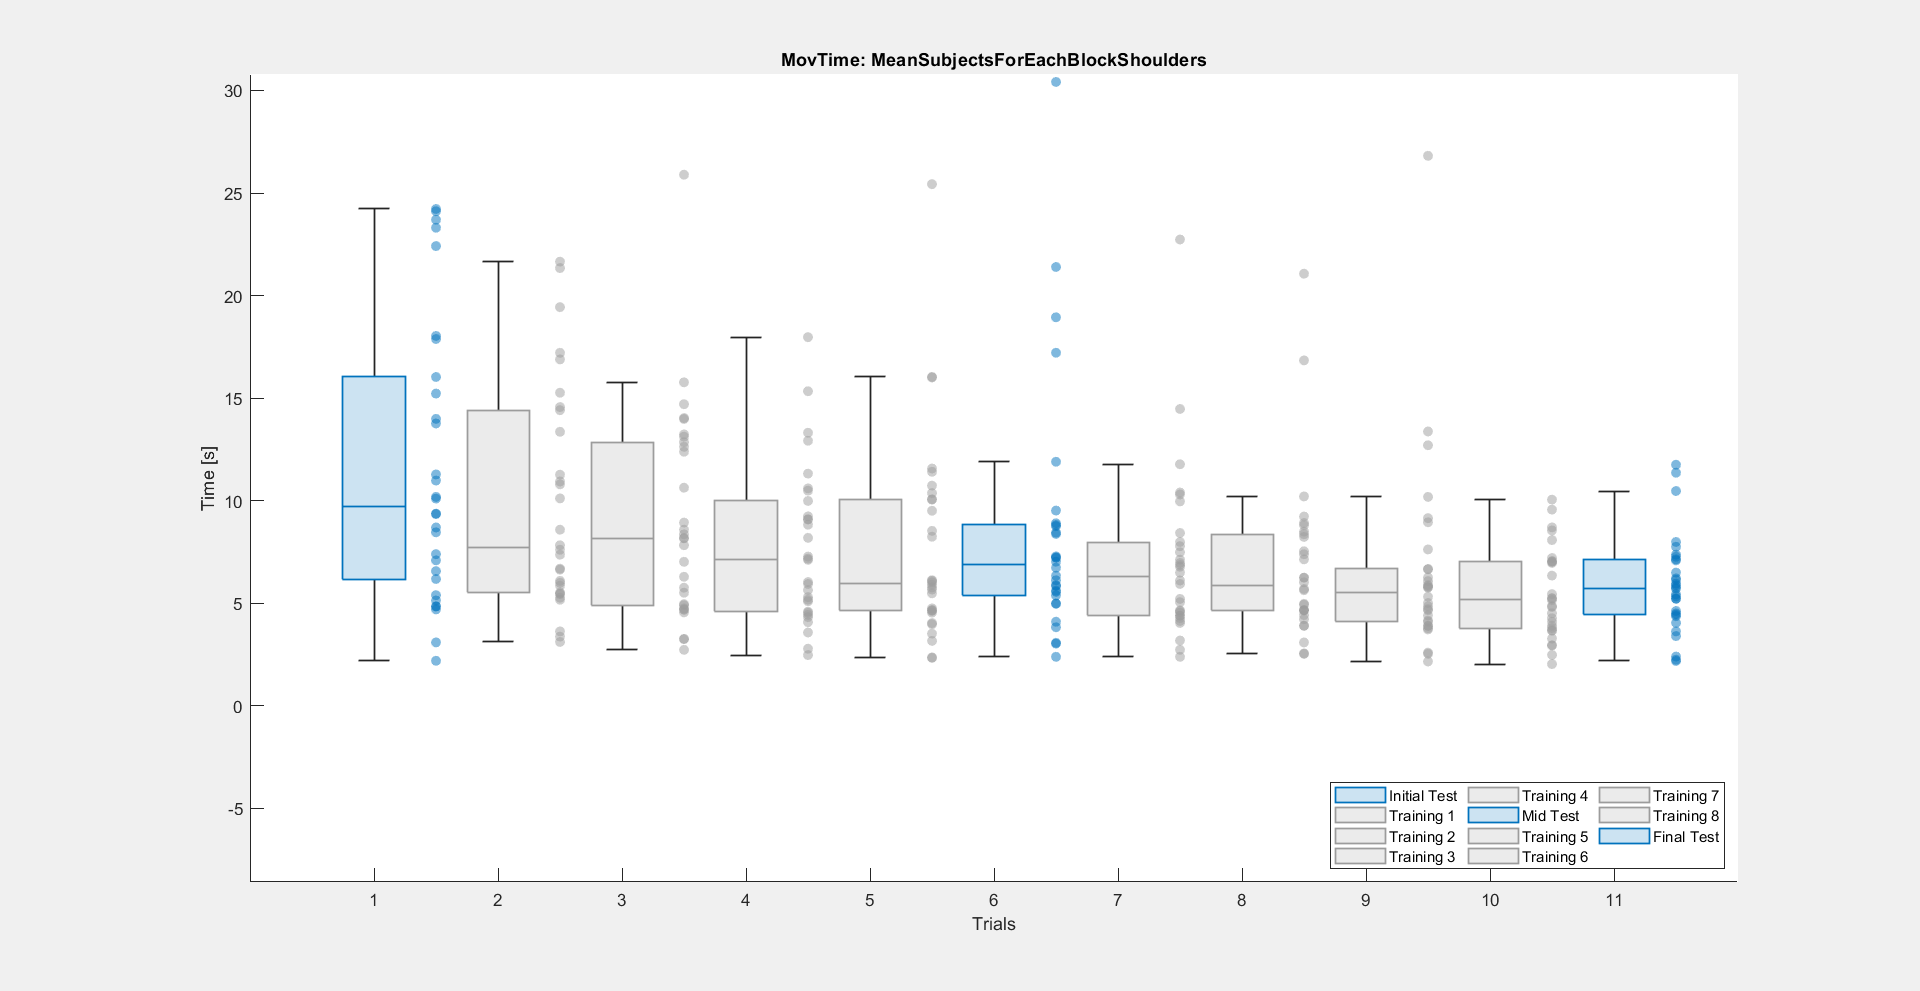

    FigName = append("MeanSubjectsForEachBlock", "Shoulders");
    Legend = {'Initial Test', 'Training 1', 'Training 2', 'Training 3', 'Training 4', 'Mid Test', 'Training 5', 'Training 6', 'Training 7', 'Training 8', 'Final Test'};

    PlotMetric(FigName, "SavedPlots", MovTimeBlock, 'MovTime', 'Time [s]', Legend, "on");

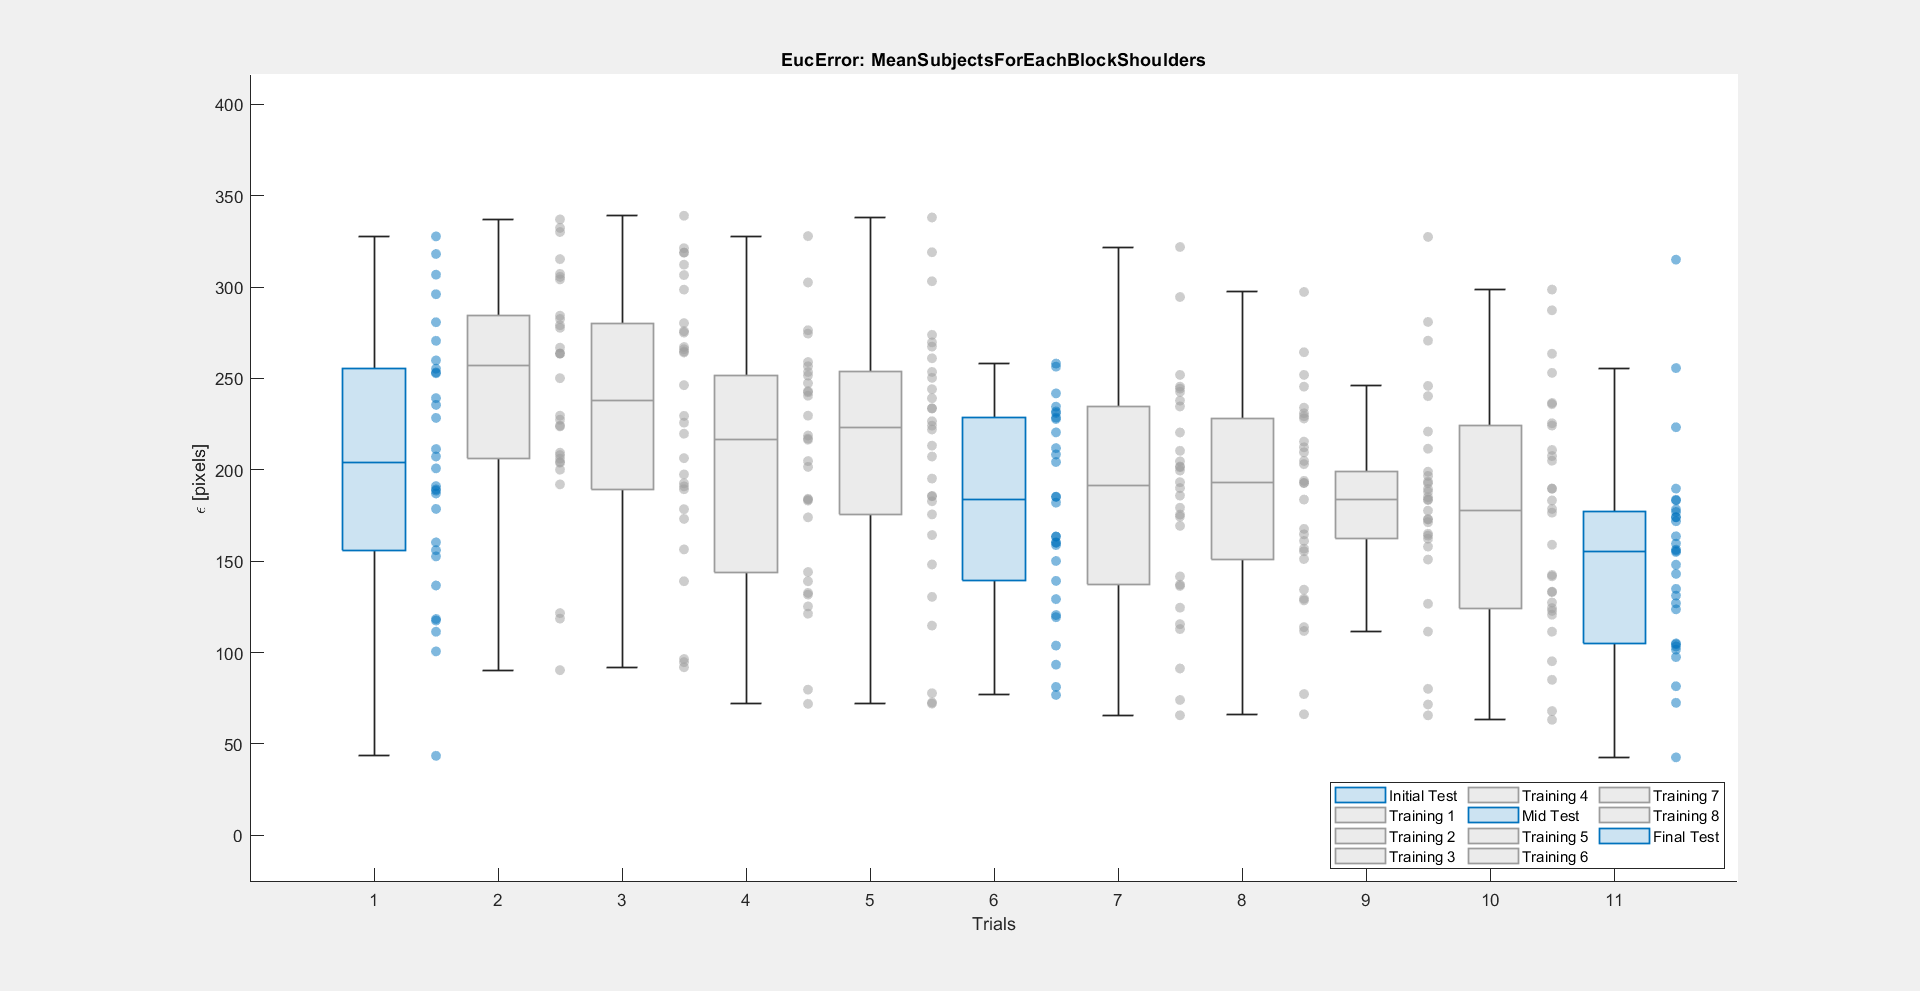

    PlotMetric(FigName, "SavedPlots", EucErrorBlock, 'EucError', '\epsilon [pixels]', Legend, "on");

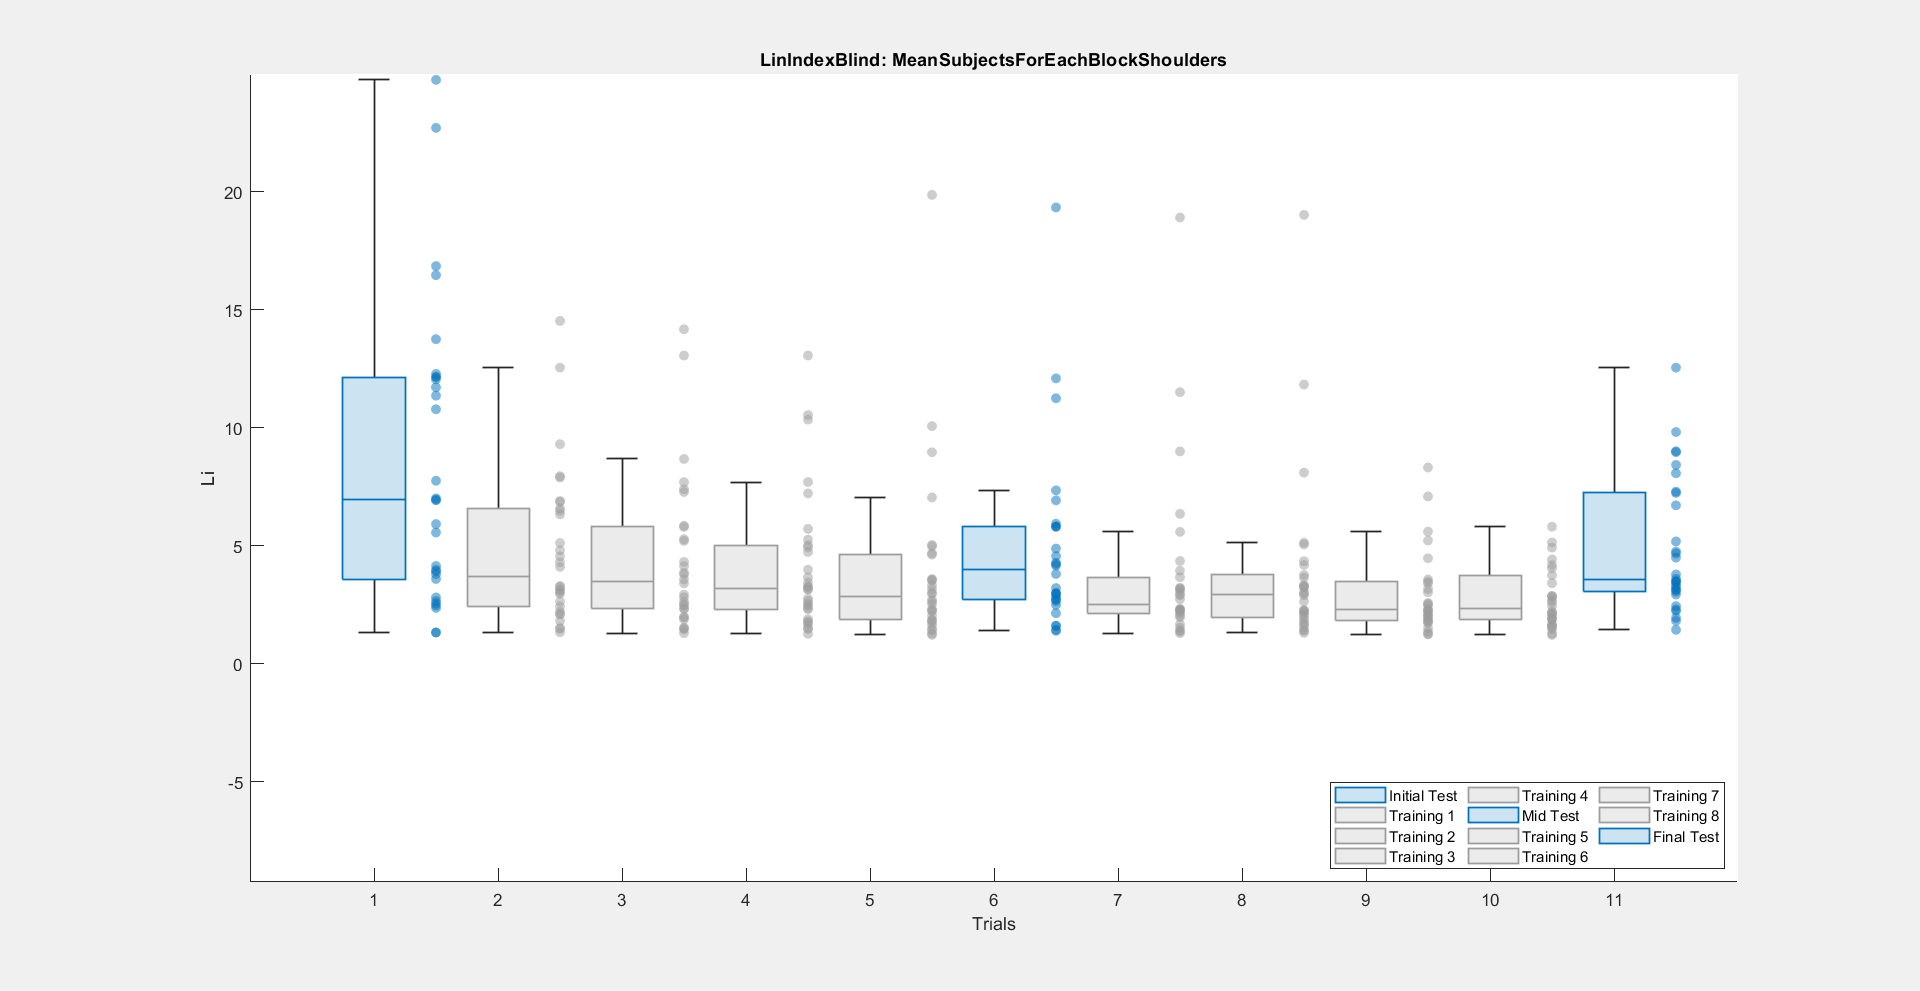

    PlotMetric(FigName, "SavedPlots", LinIndexBlock, 'LinIndexBlind', 'Li', Legend, "on");

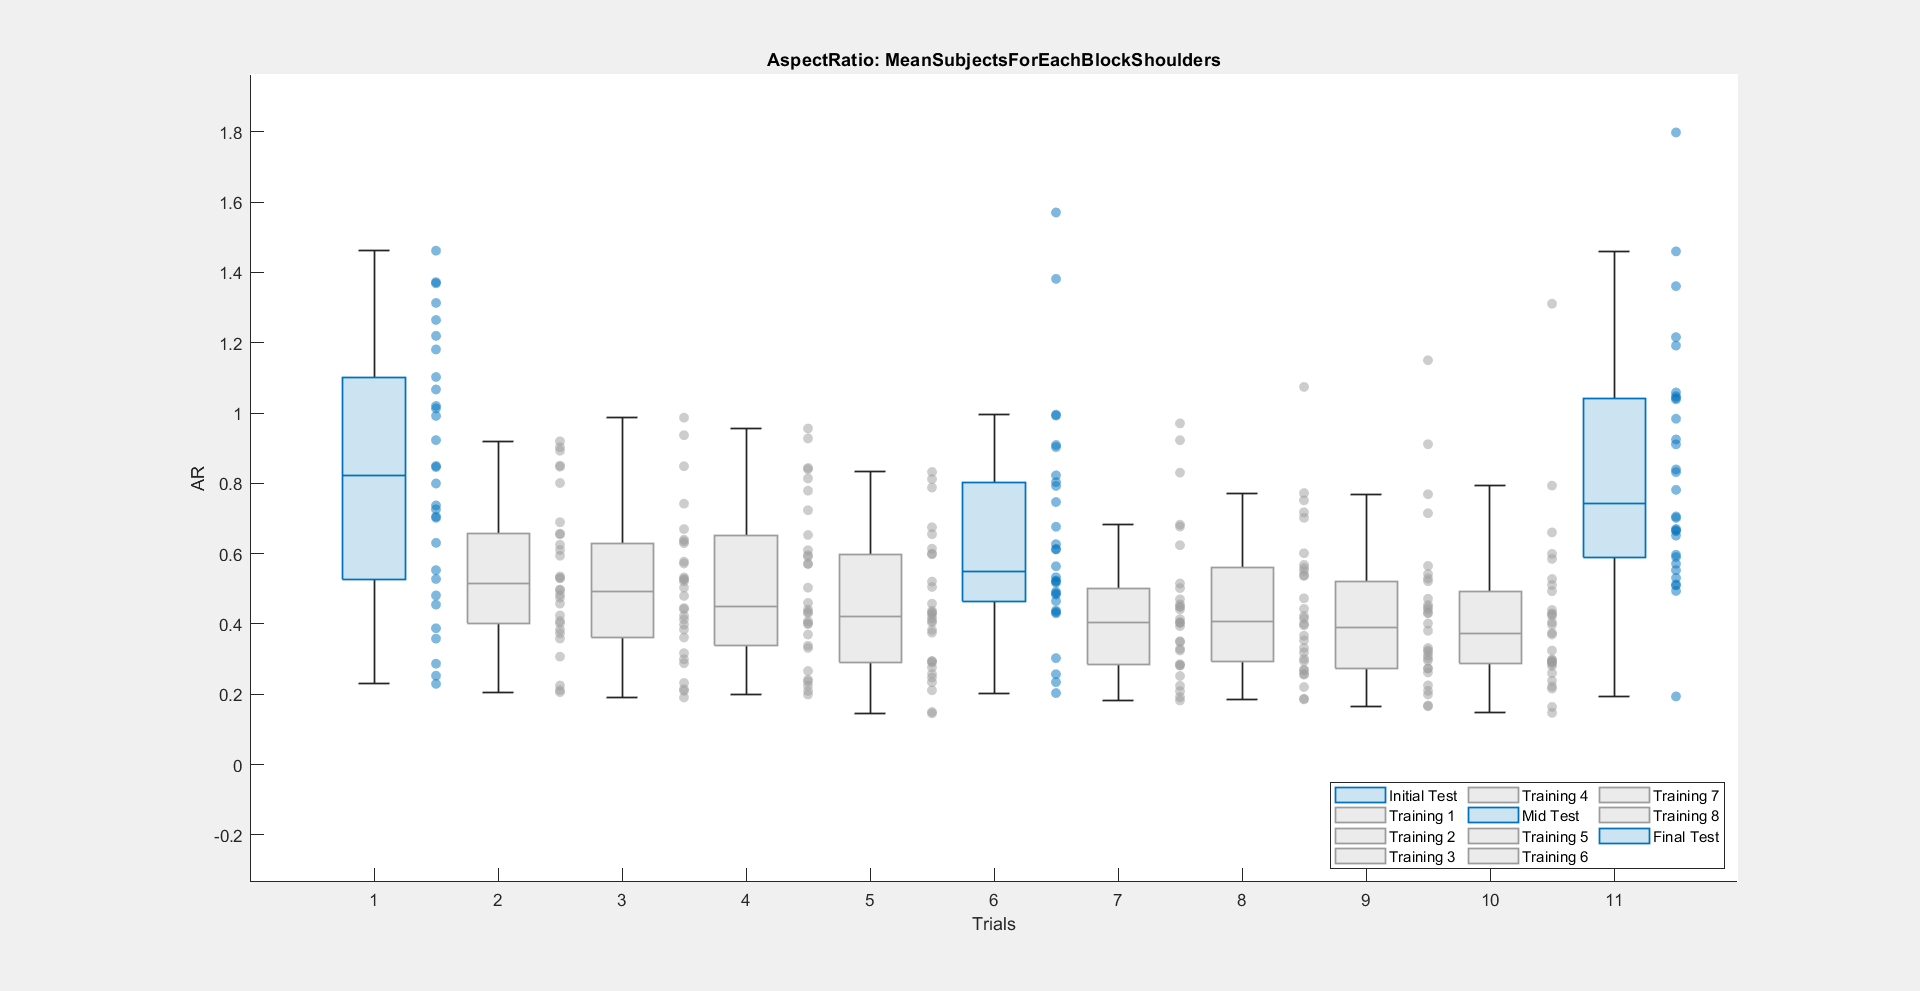

    PlotMetric(FigName, "SavedPlots", AspectRatioBlock, 'AspectRatio', 'AR', Legend, "on");

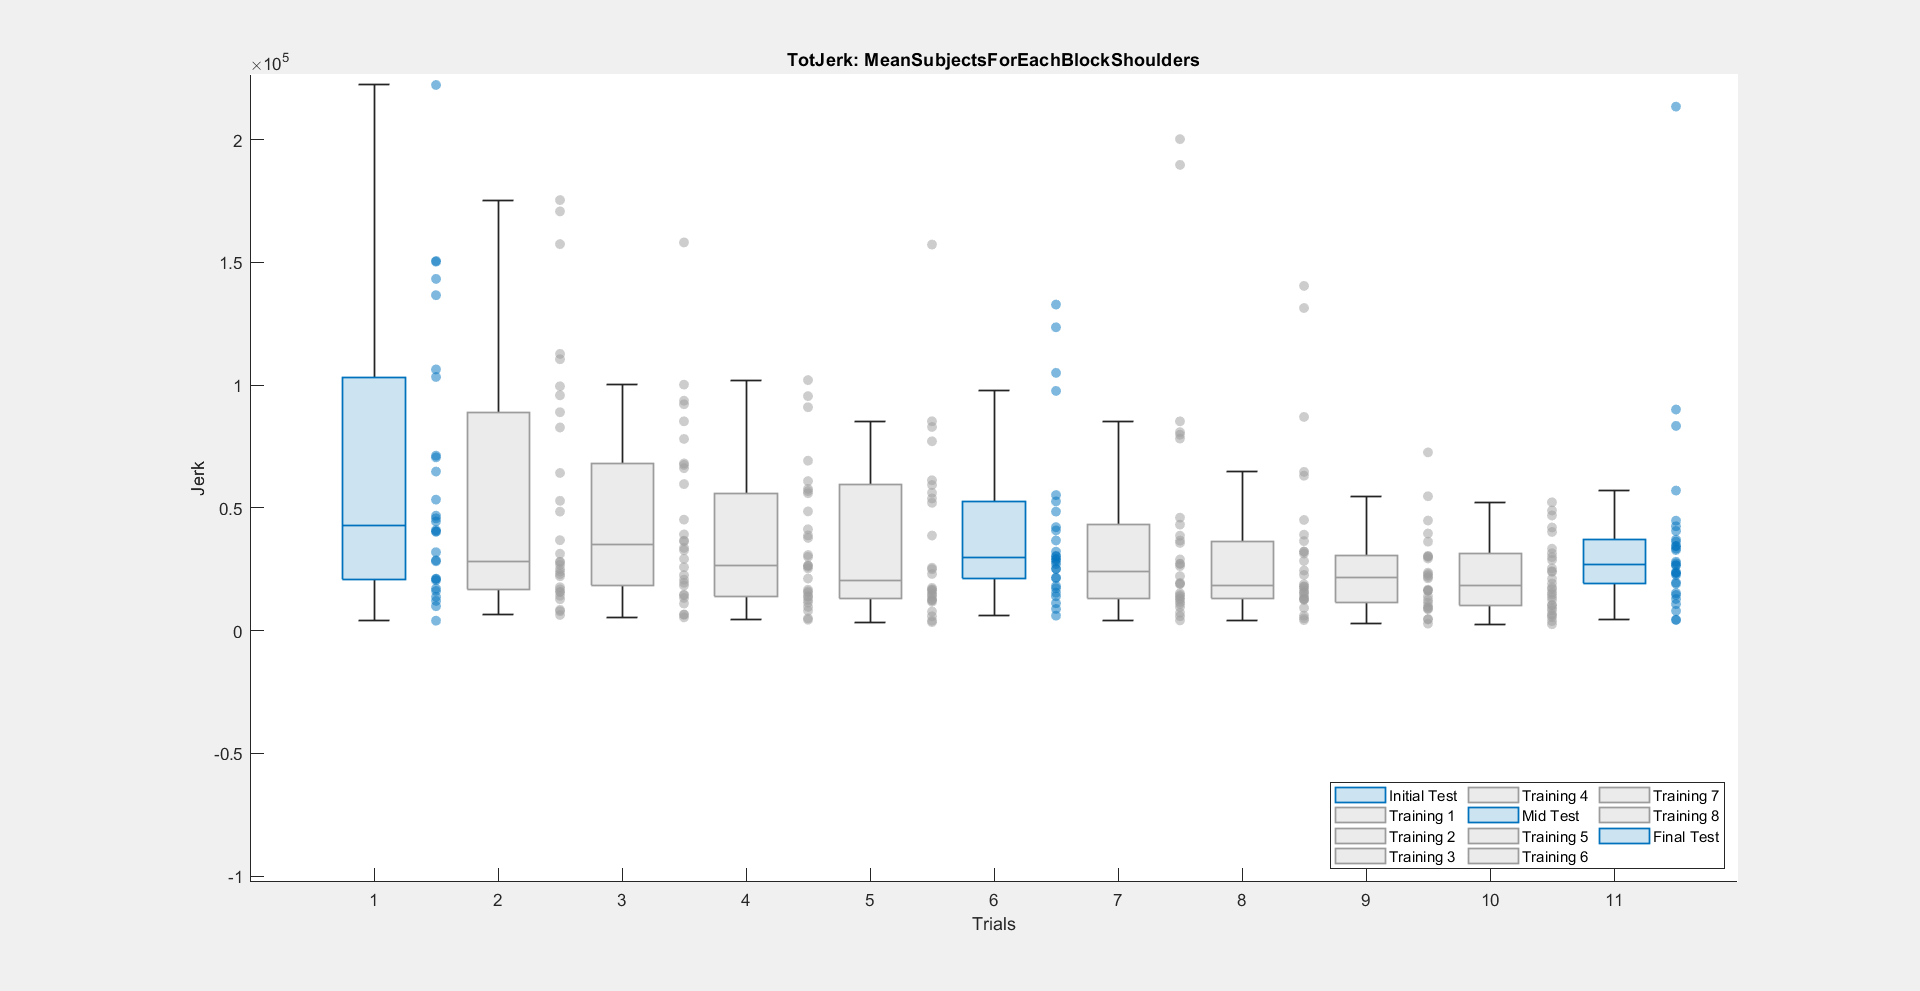

    PlotMetric(FigName, "SavedPlots", TotJerkBlock, 'TotJerk', 'Jerk', Legend, "on");

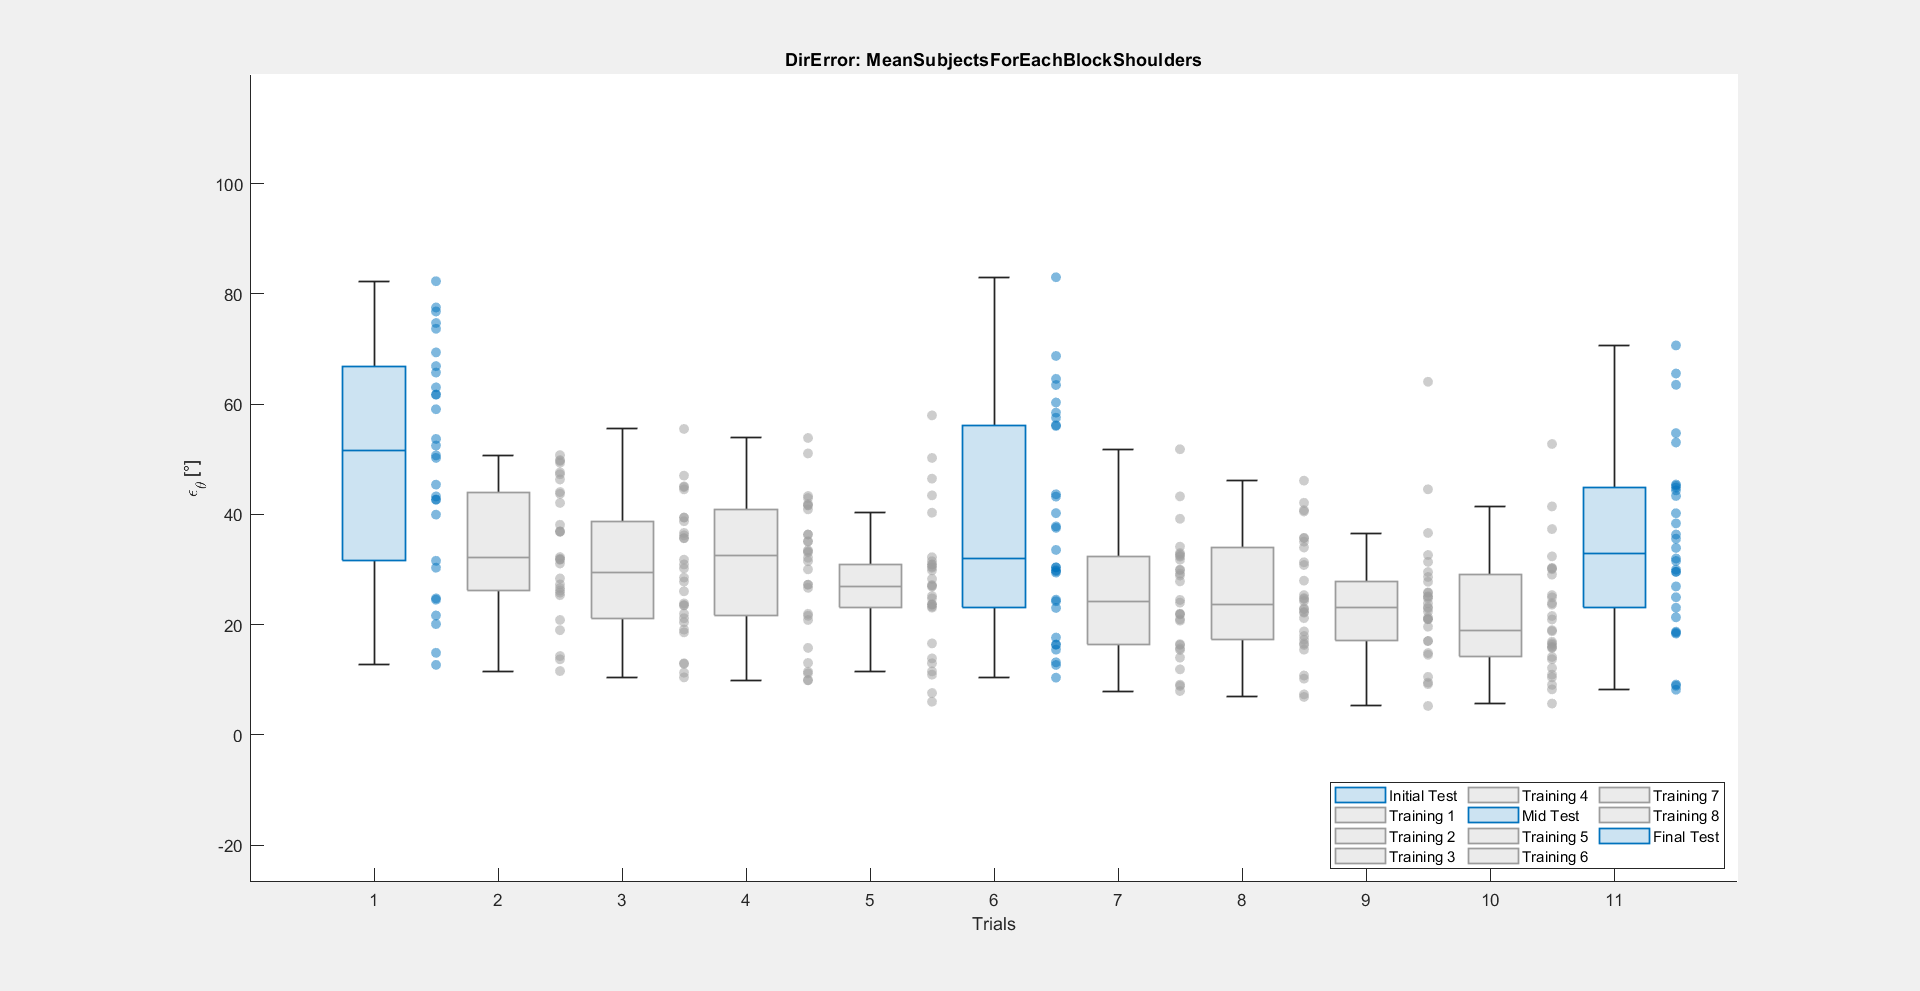

    PlotMetric(FigName, "SavedPlots", DirErrorBlock, 'DirError', '\epsilon_{\theta} [°]', Legend, "on");

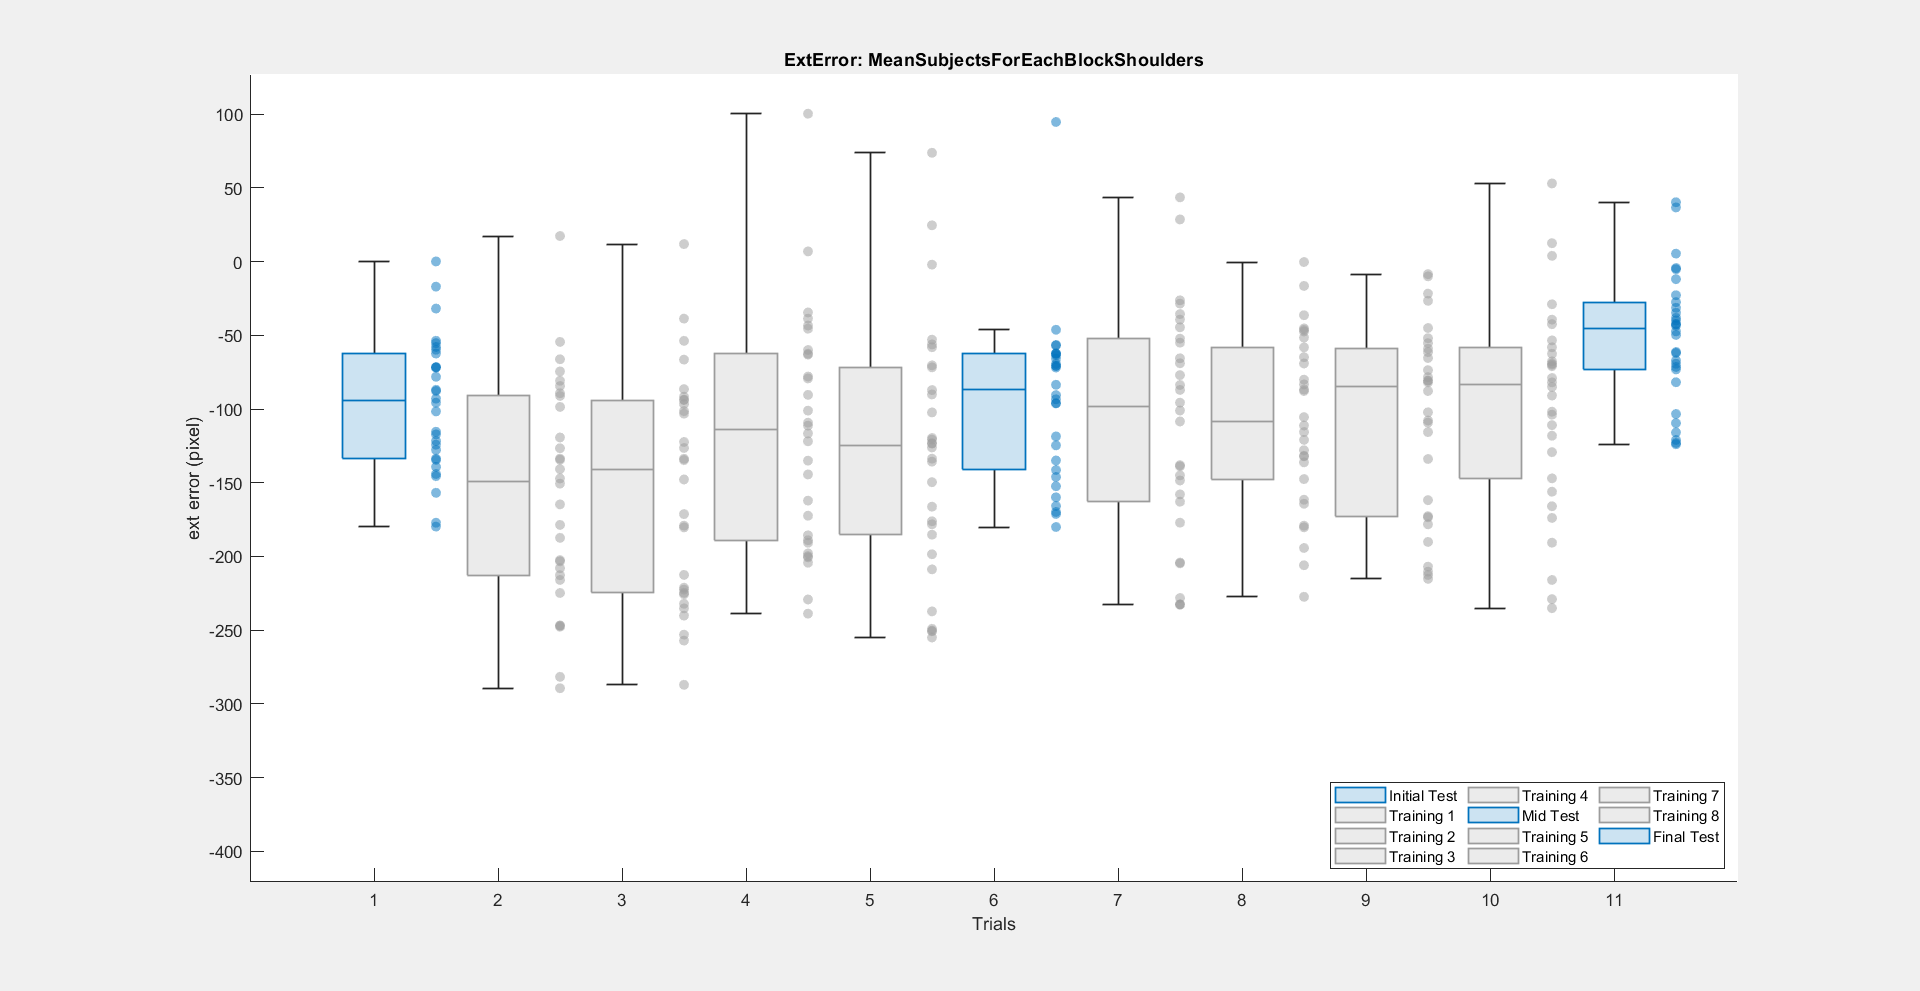

    PlotMetric(FigName, "SavedPlots", ExtErrorBlock, 'ExtError', 'ext error (pixel)', Legend, "on");

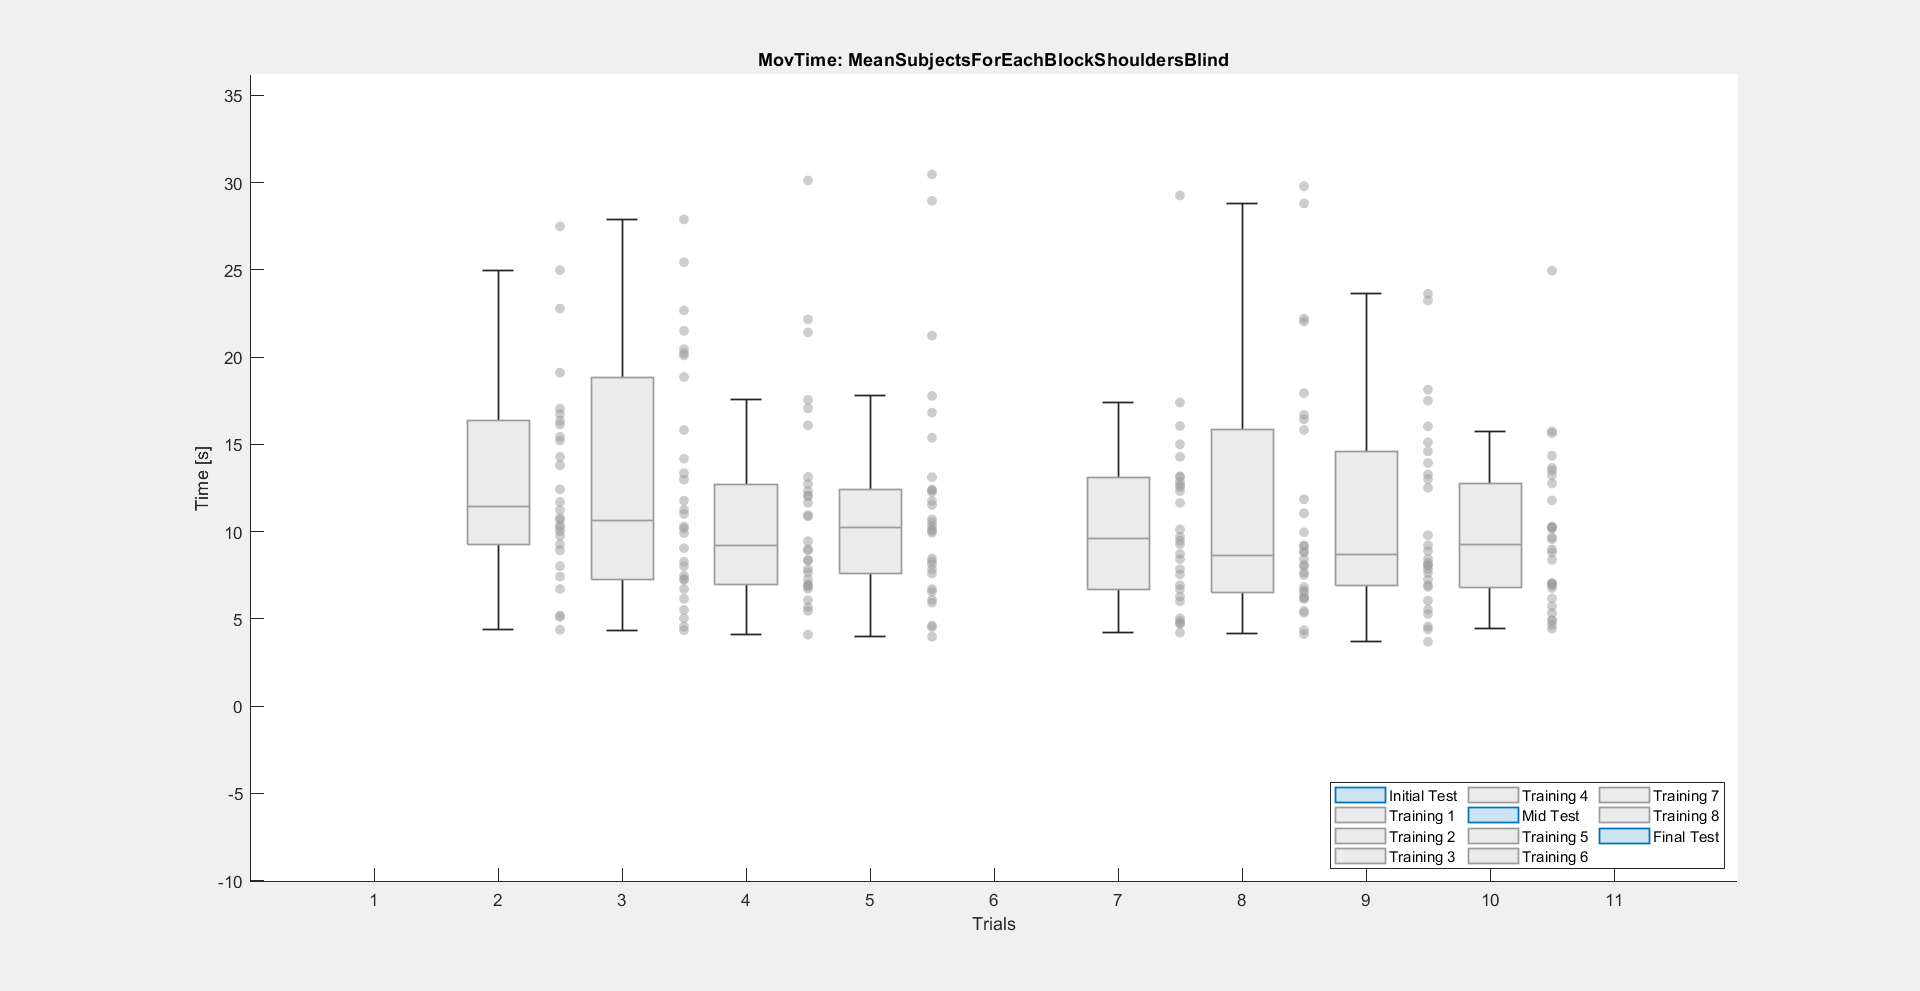


    FigName = append("MeanSubjectsForEachBlock", "ShouldersBlind");
    
    PlotMetric(FigName, "SavedPlots", MovTimeBlockBlind, 'MovTime', 'Time [s]', Legend, "on");

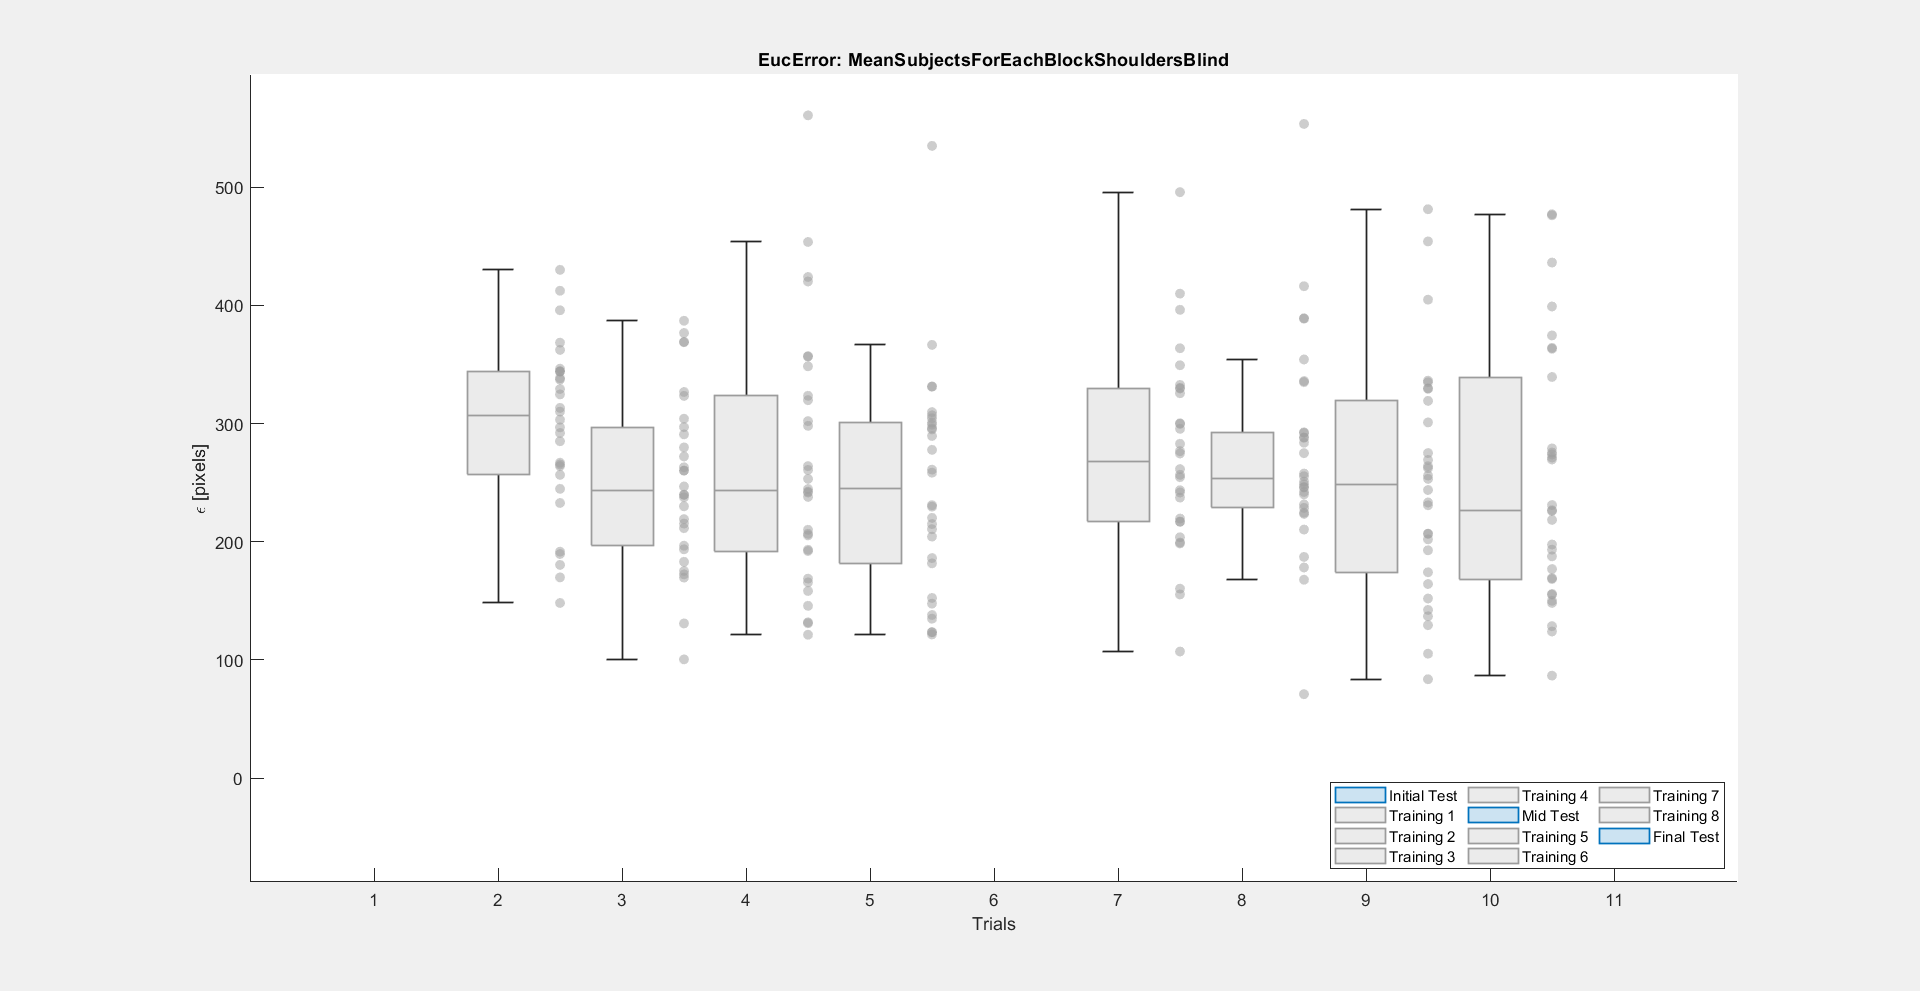

    PlotMetric(FigName, "SavedPlots", EucErrorBlockBlind, 'EucError', '\epsilon [pixels]', Legend, "on");

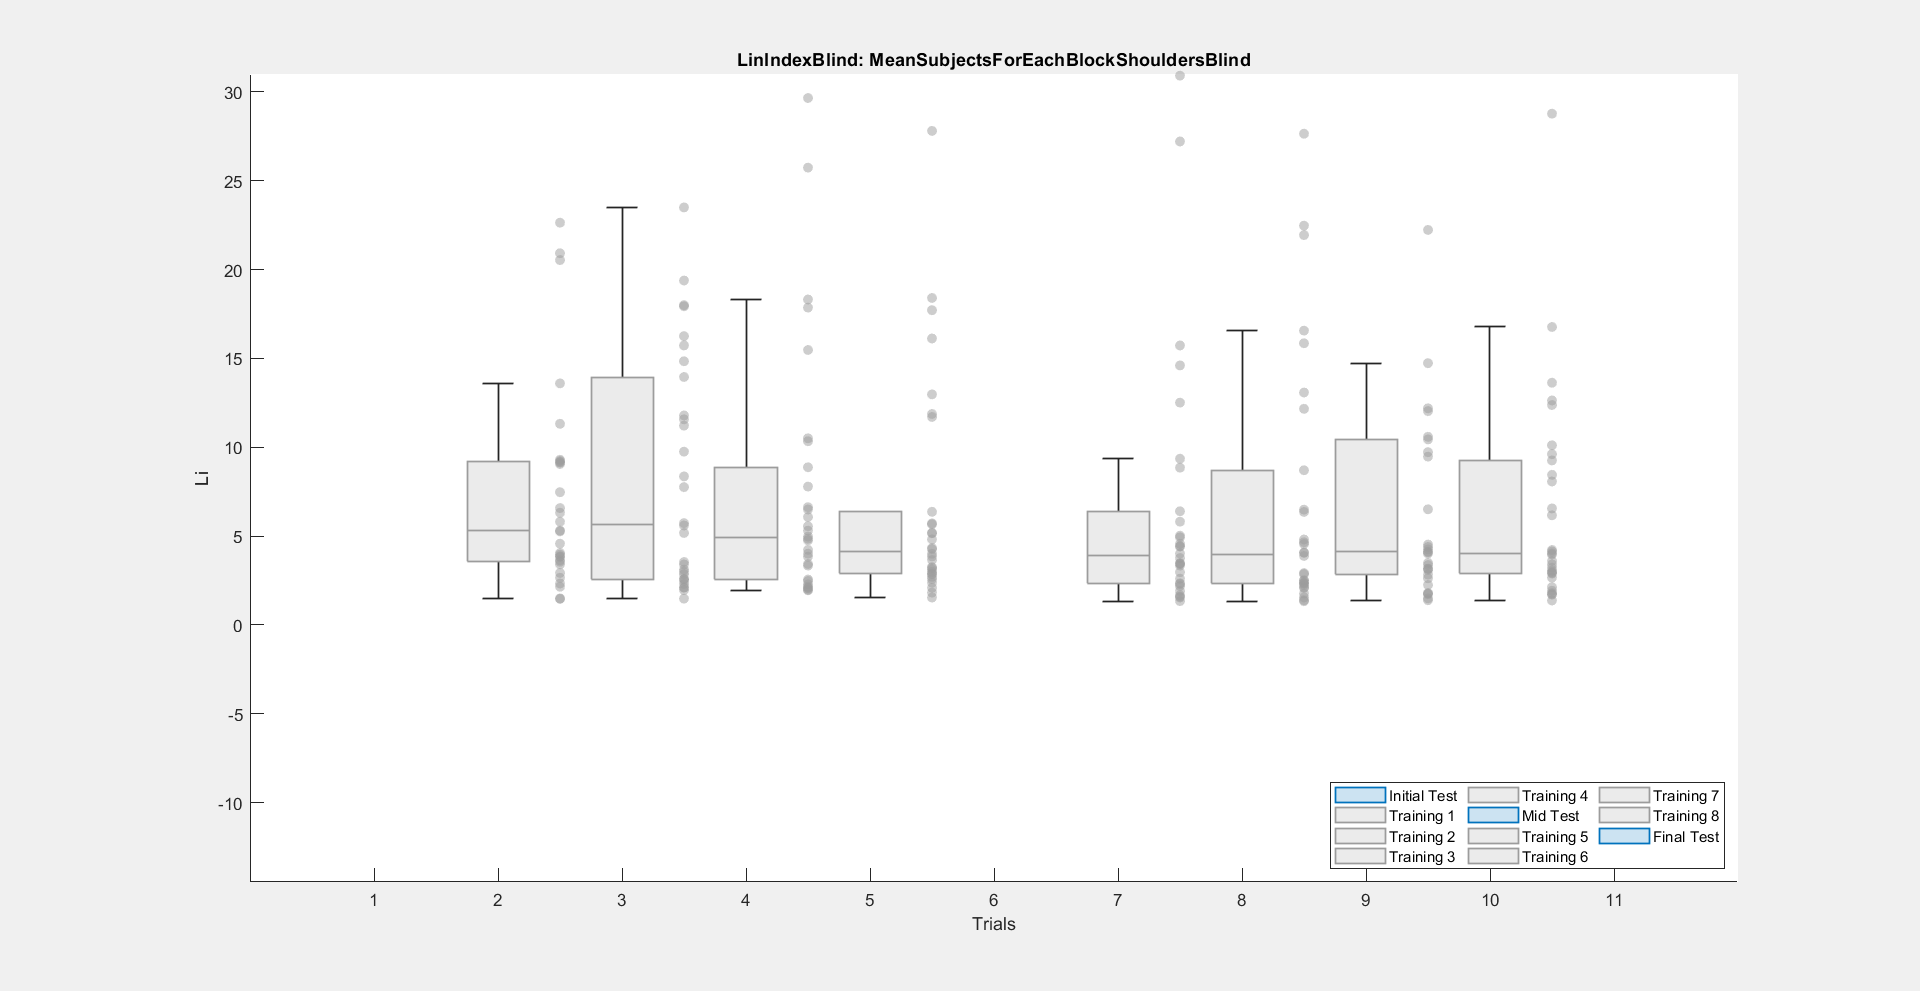

    PlotMetric(FigName, "SavedPlots", LinIndexBlockBlind, 'LinIndexBlind', 'Li', Legend, "on");

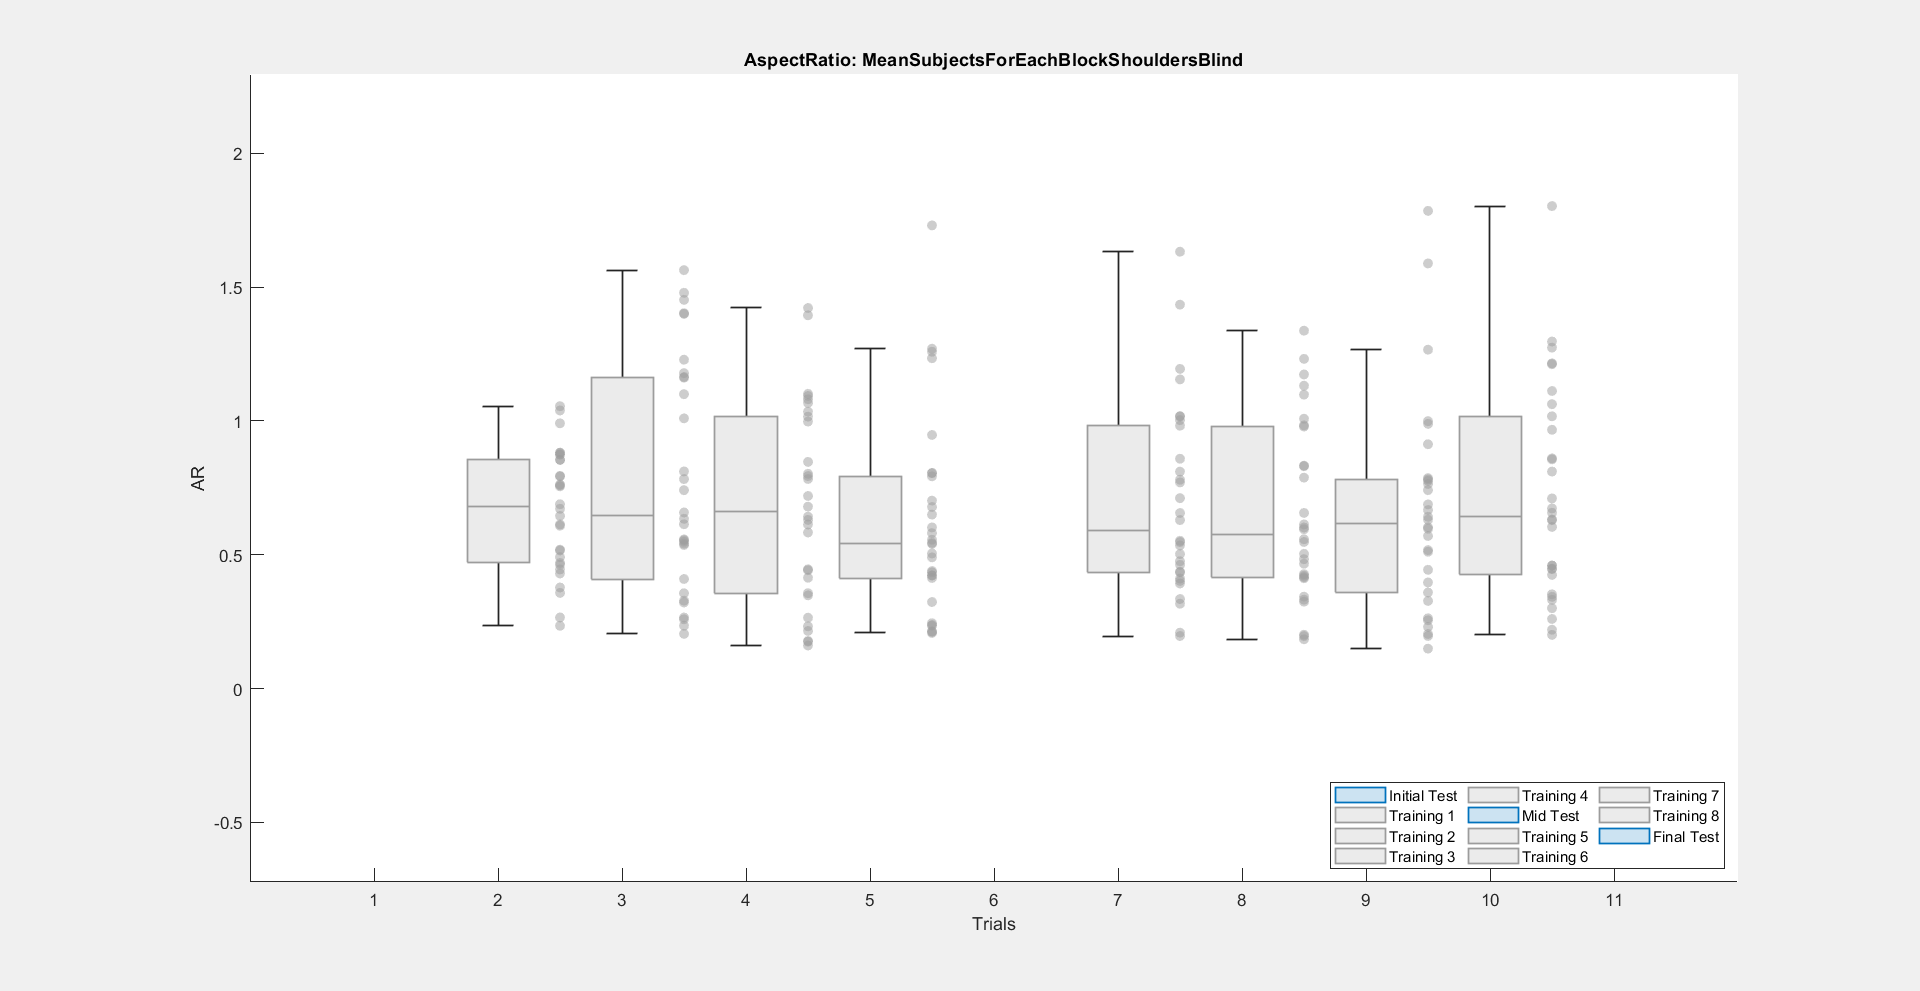

    PlotMetric(FigName, "SavedPlots", AspectRatioBlockBlind, 'AspectRatio', 'AR', Legend, "on");

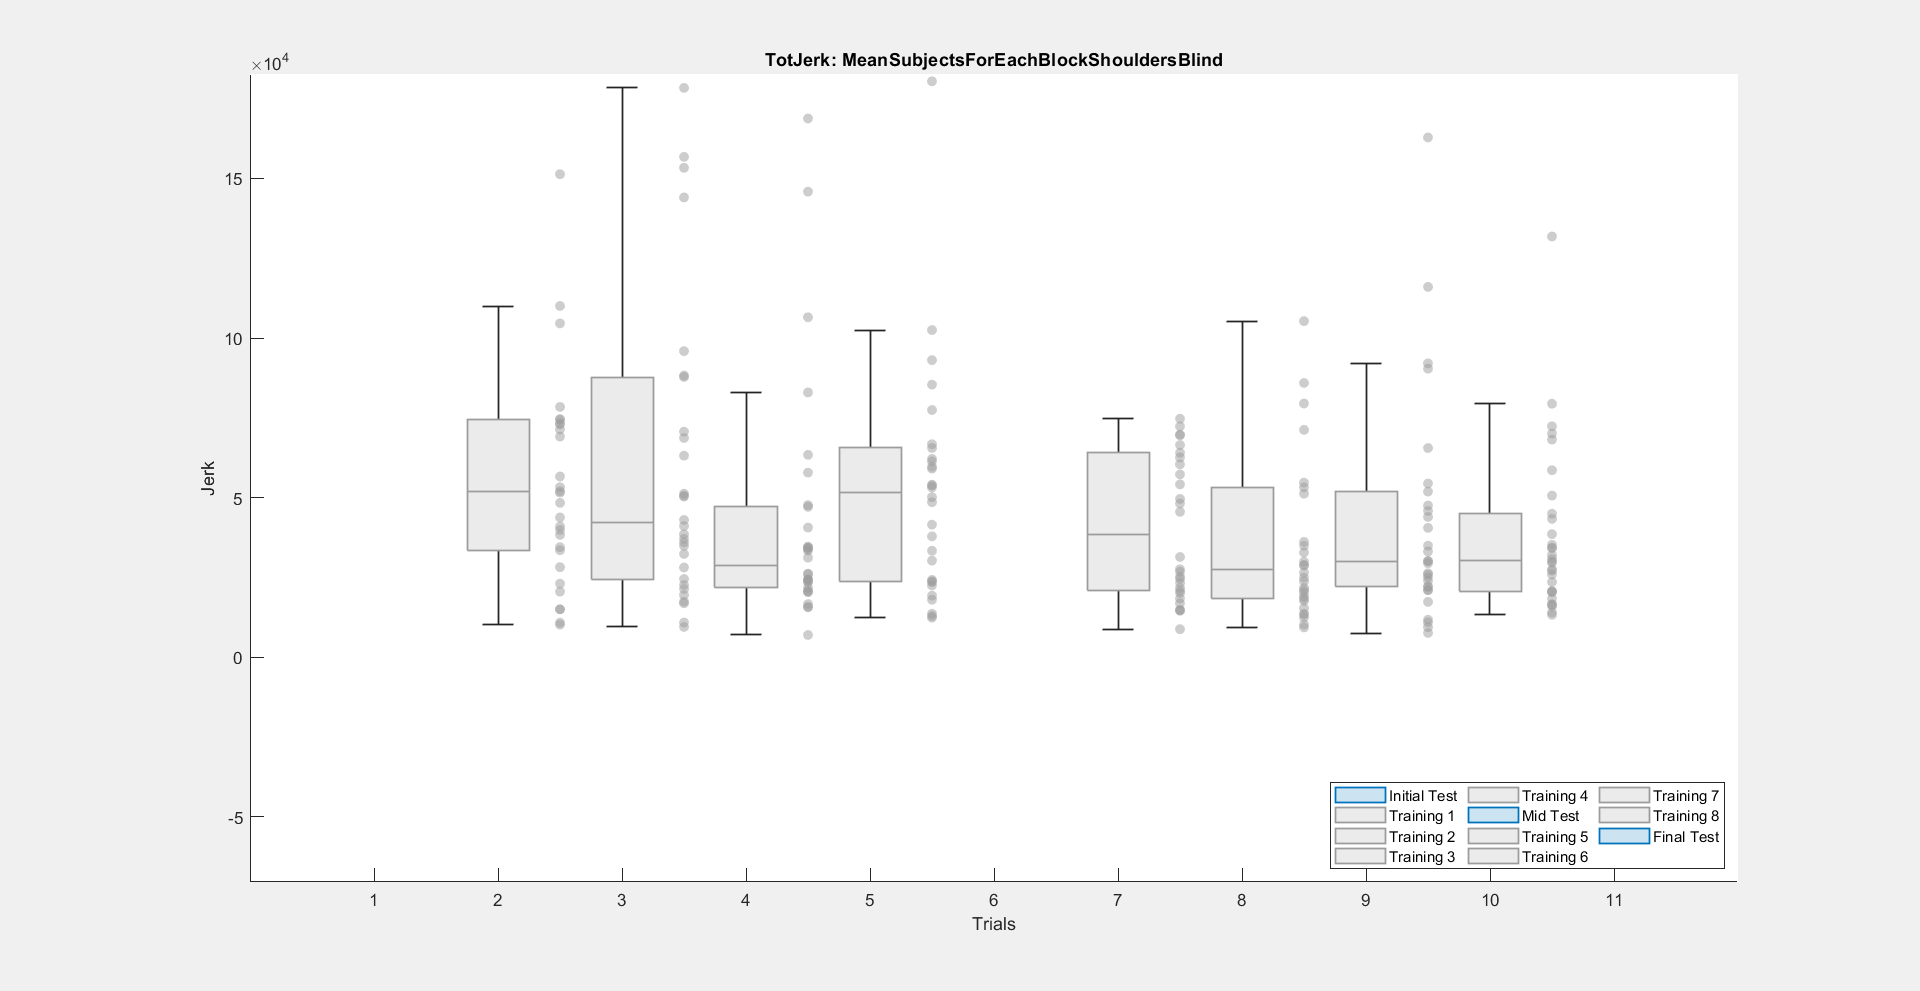

    PlotMetric(FigName, "SavedPlots", TotJerkBlockBlind, 'TotJerk', 'Jerk', Legend, "on");

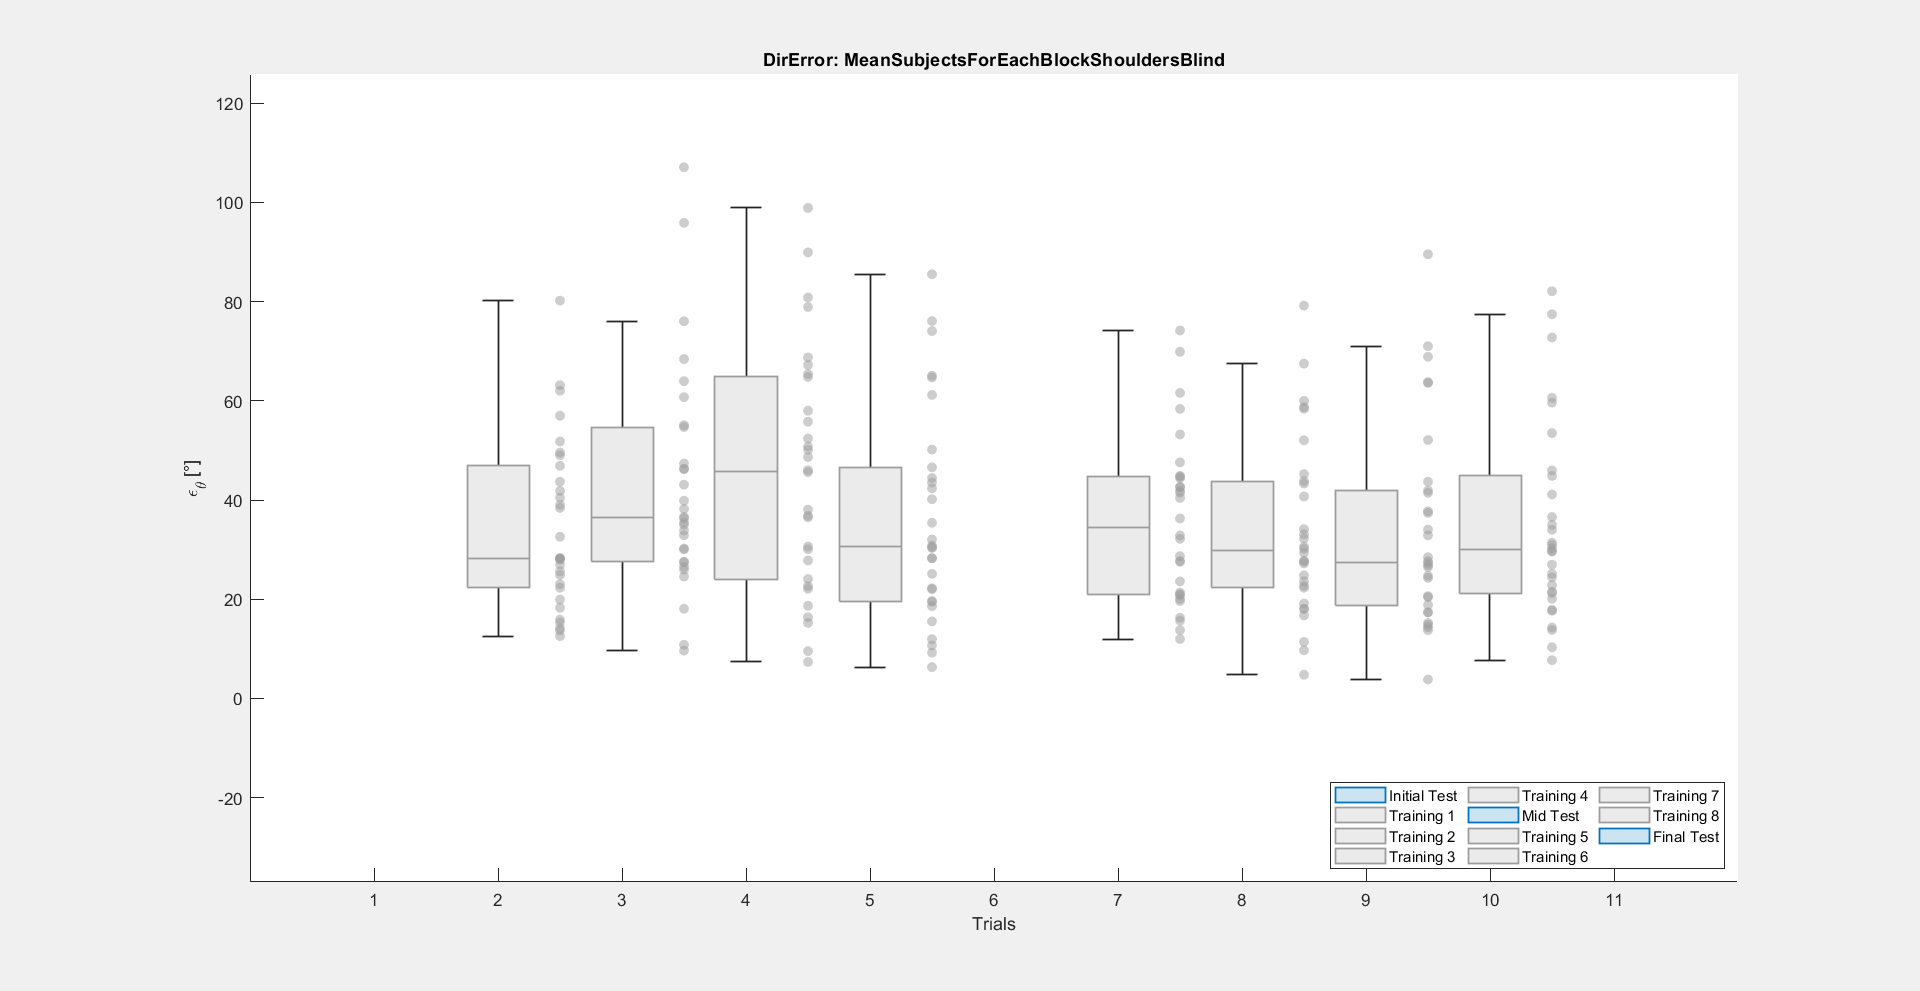

    PlotMetric(FigName, "SavedPlots", DirErrorBlockBlind, 'DirError', '\epsilon_{\theta} [°]', Legend, "on");

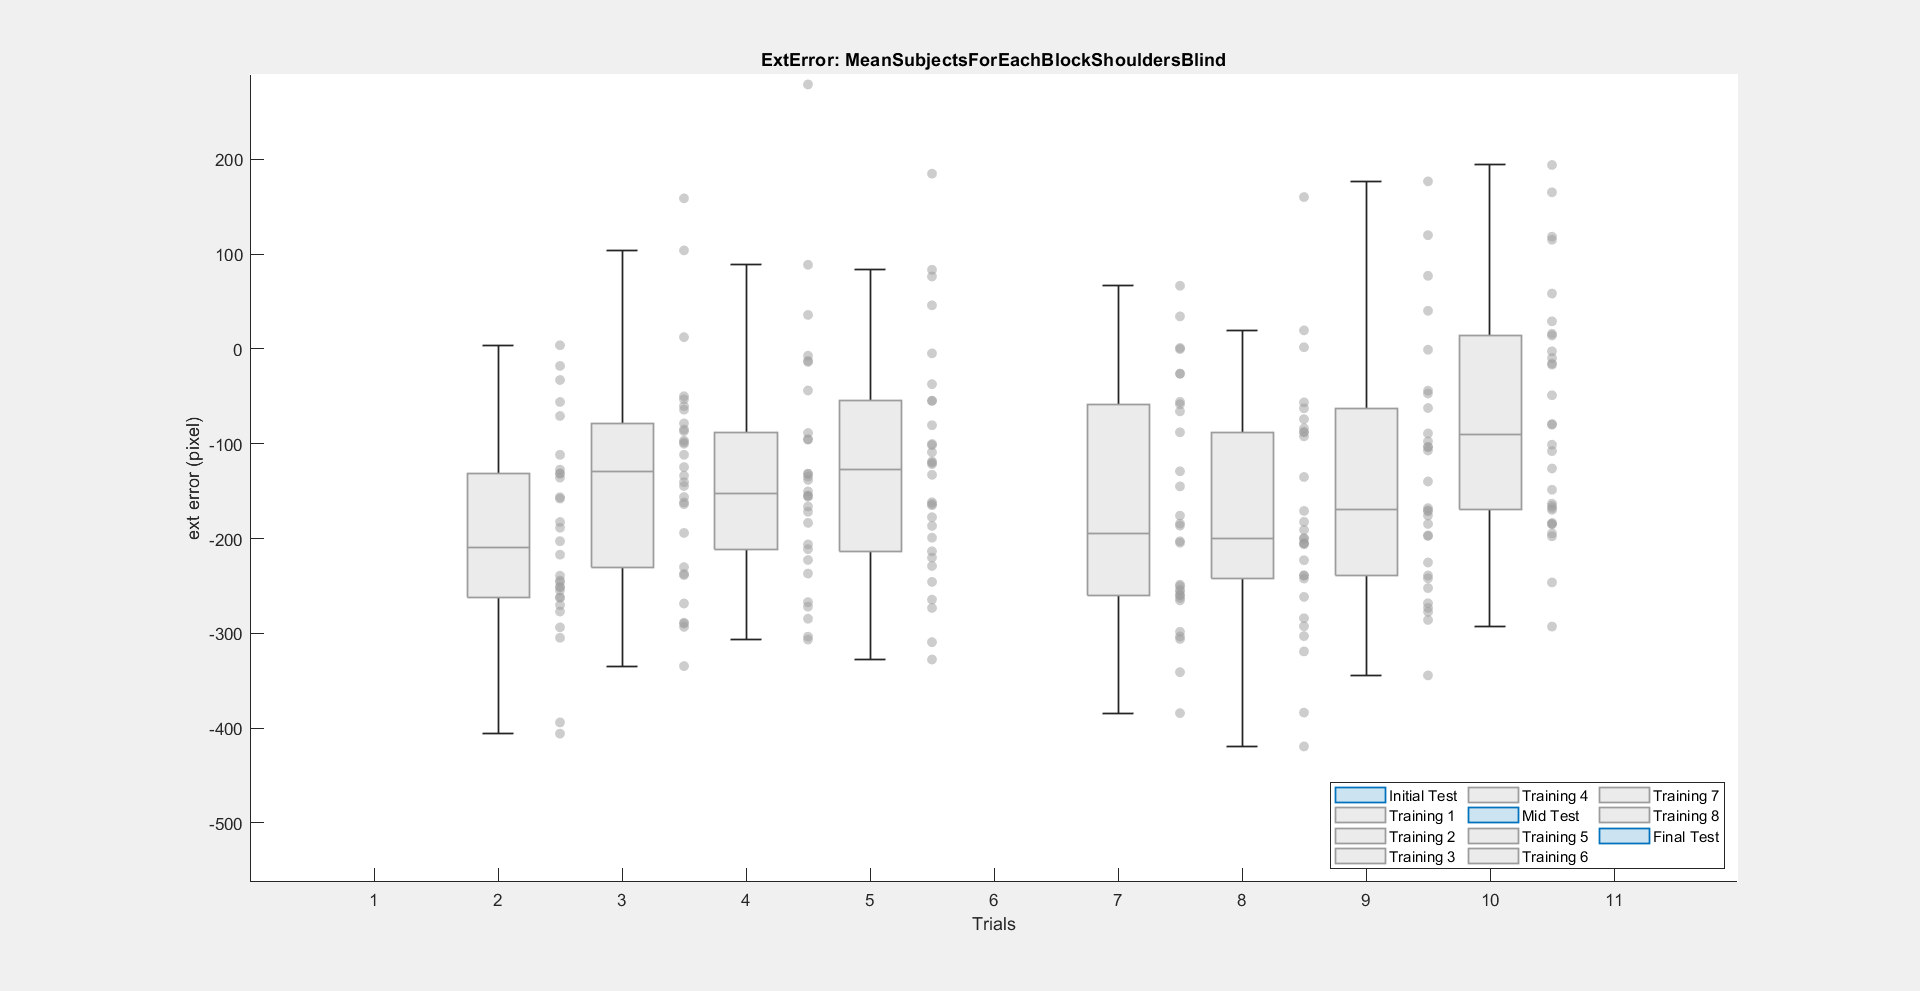

    PlotMetric(FigName, "SavedPlots", ExtErrorBlockBlind, 'ExtError', 'ext error (pixel)', Legend, "on");